## **Proposta del controllore lineare**

Come evidenziato dallo script precedente, il controllore fornito dalla traccia è molto efficiente, ma prevede un'azione di controllo esagerata che porta la soluzione ad essere, realisticamente, di difficile realizzabilità. Per la trattazione successiva è stato deciso di limitarci a due casi in particolare: il primo in cui è stata considerata un'azione di controllo limitata a casi reali, e un secondo caso, irrealistico, in cui si è cercato un valore ottimale considerando un azione di controllo illimitata.

Di seguito mostriamo il data-sheet di un motore reale, utilizzato per definire il limite dell'azione di controllo:

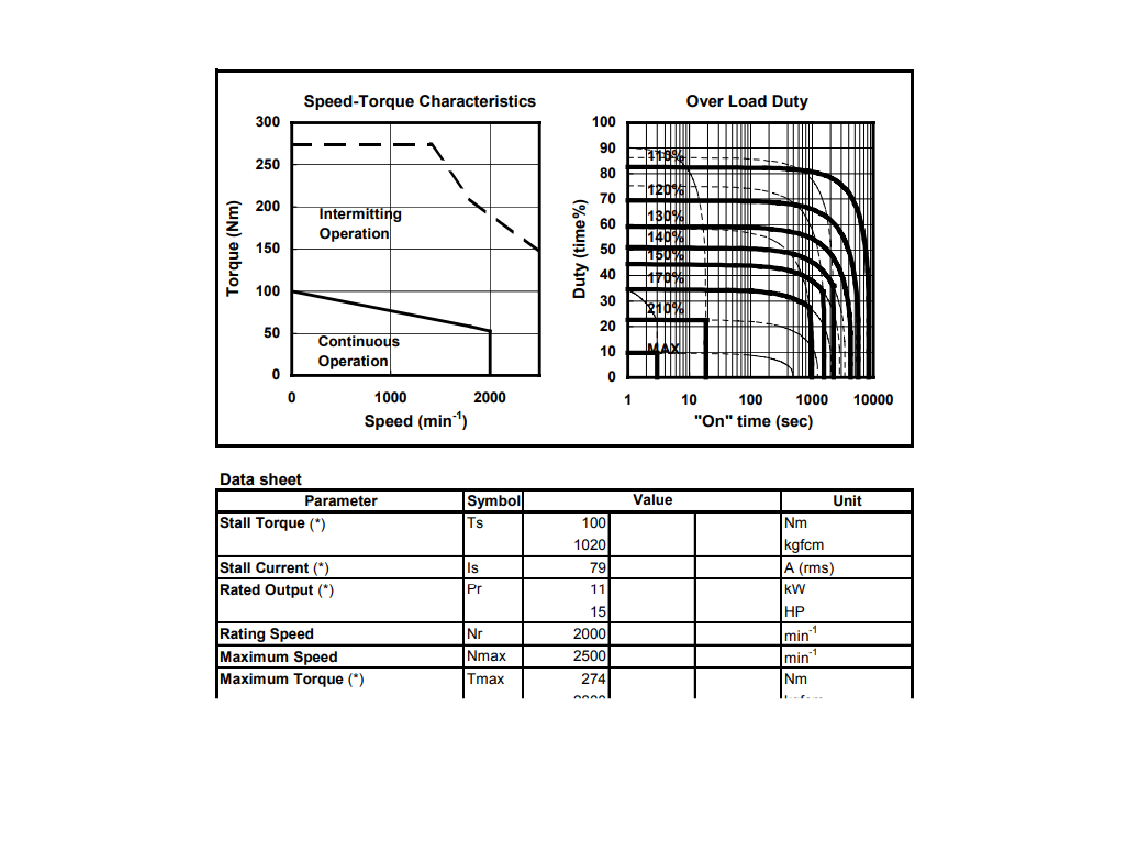

imshow(imread("img/datasheet.png"))

ovvero nell'ordine di $300$. Ovviamente per il secondo caso, non esiste un vero e proprio limite di performance, poichè è possibile spingere l'azione di controllo all'infinito. Sono stati effettuati comunque questo tipo di esperimenti per compararli a ciò che effettivamente fosse realizzabile realisticamente, ma non sono riportati i risultati a causa della loro inconsistenza fisica.

## **Ricapitolazione**

Partendo dal sistema linearizzato, possiamo ottenere il controllore per tale sistema, e attraverso opportune procedure di sintesi si otterrà un controllore per il sistema non lineare del tipo: 


$$u -u_e= -K (x-x_e) + k_r (r_{nl} -\pi)$$


per le motivazioni descritte nel precedente script.

Nella seguente trattazione si procederà con l'analisi di differenti tecniche di sintesi di un controllore lineare, basate sulla retroazione di stato. Per effettuare un controllo basato su questo approccio, per un sistema lineare, o linearizzato, c'è bisogno che valga la proprietà di raggiungibilità.

A=[0 1; 9.81 -0.1];
B=[0; 1];
C=[1 0];
D=0;
%matrice di raggiungibilità
W_R=[B A*B];
%verifichiamo che rango sia uguale a max(n righe, n colonne) di W_R
rank(W_R)

ans = 2

% Il sistema è raggiungibile

Il rango della matrice di raggiungibilità è pieno, di conseguenza il sistema è raggiungibile.

## Pole placement tramite funzione place di Matlab

Una prima proposta di miglioramento del controllore prevede l'utilizzo della funzione place di Matlab per piazzare i poli a ciclo chiuso in maniera arbitraria. Progettare $K$ affinchè il sistema sia asintoticamente stabile è sempre possibile se il sistema è raggiungibile, il controllore può posizionare gli autovalori della matrice dinamica e quindi alterare la dinamica dell'uscita. Sono stati effettuati numerosi esperimenti e i poli sono stati scelti in modo tale da permettere un'azione di controllo contenuta nei limiti autoimposti. Per questi controllori proposti è stato definito un nuovo schema simulink, anche se analogo al caso precedente del controllore $v_0$.

%caso reale umax= 300
p=[-8 -10]; % posizione desiderata dei poli 
%caso estremo umax = +inf
%p= [-100 -200]
K=place(A,B,p);
kr=-1/(C*inv(A-B*K)*B);

## Test sul sistema lineare

Per analizzare le performance del controllo, si è effettuato un test preliminare sul sistema linearizzato per giudicare la bontà di quanto progettato.

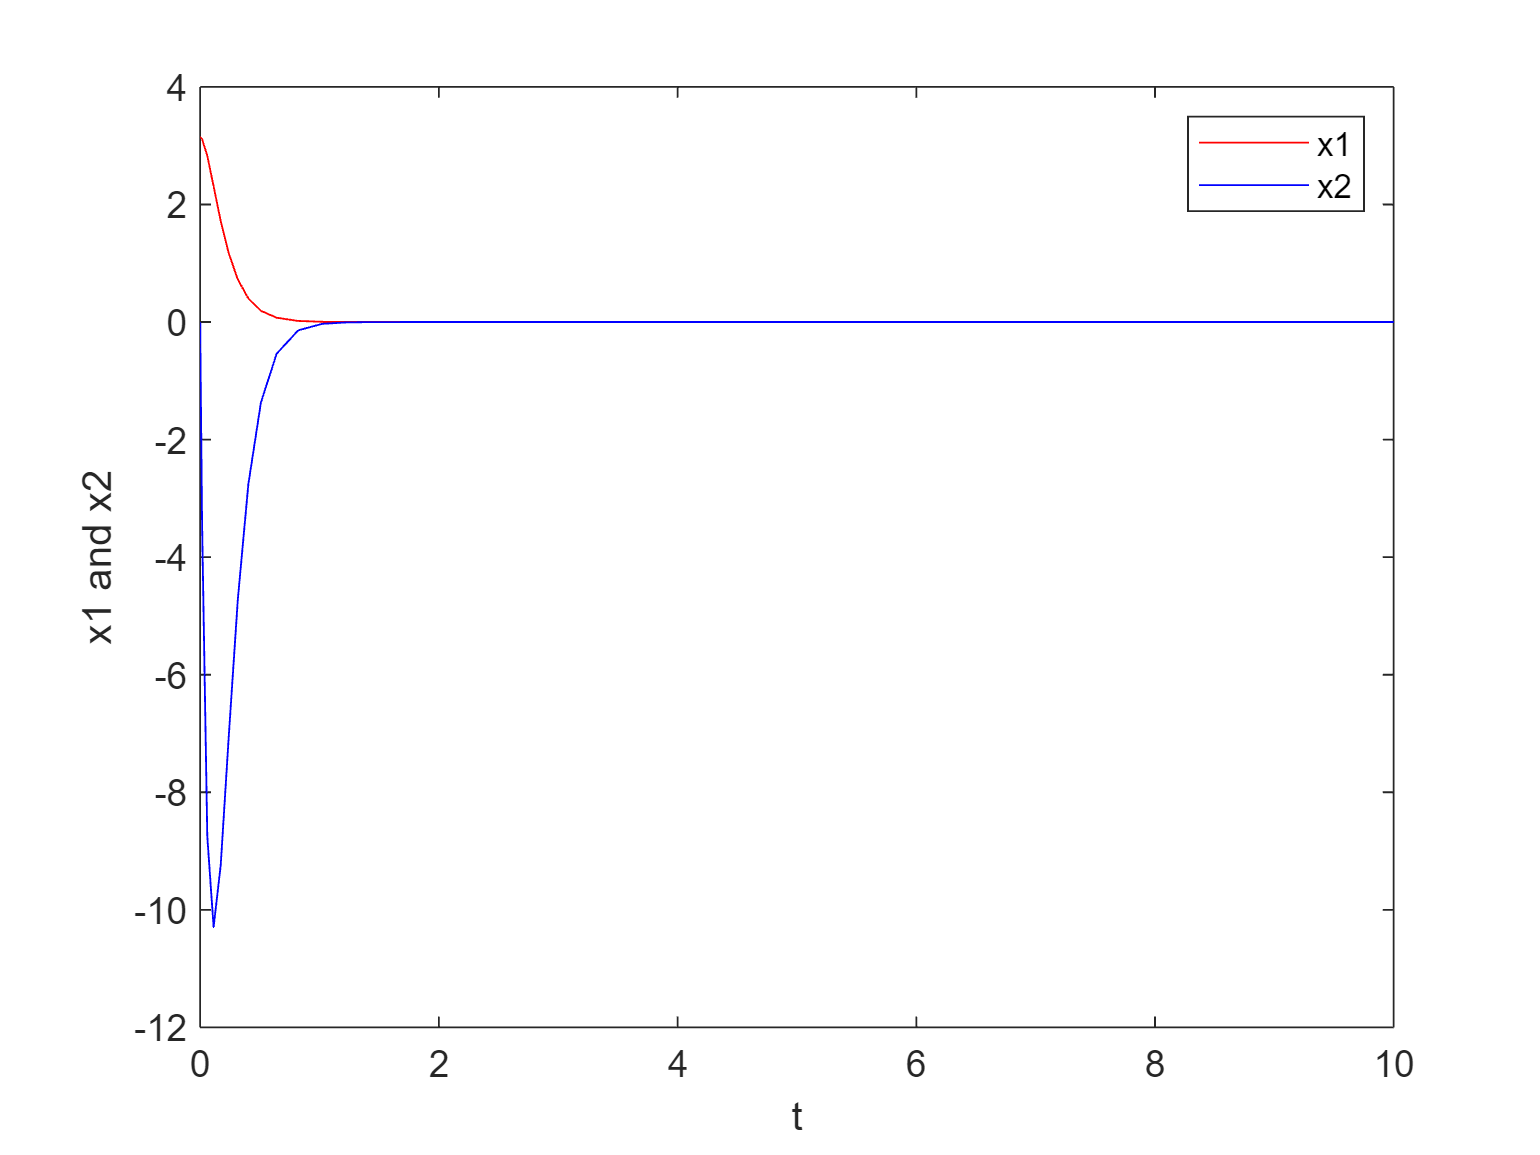

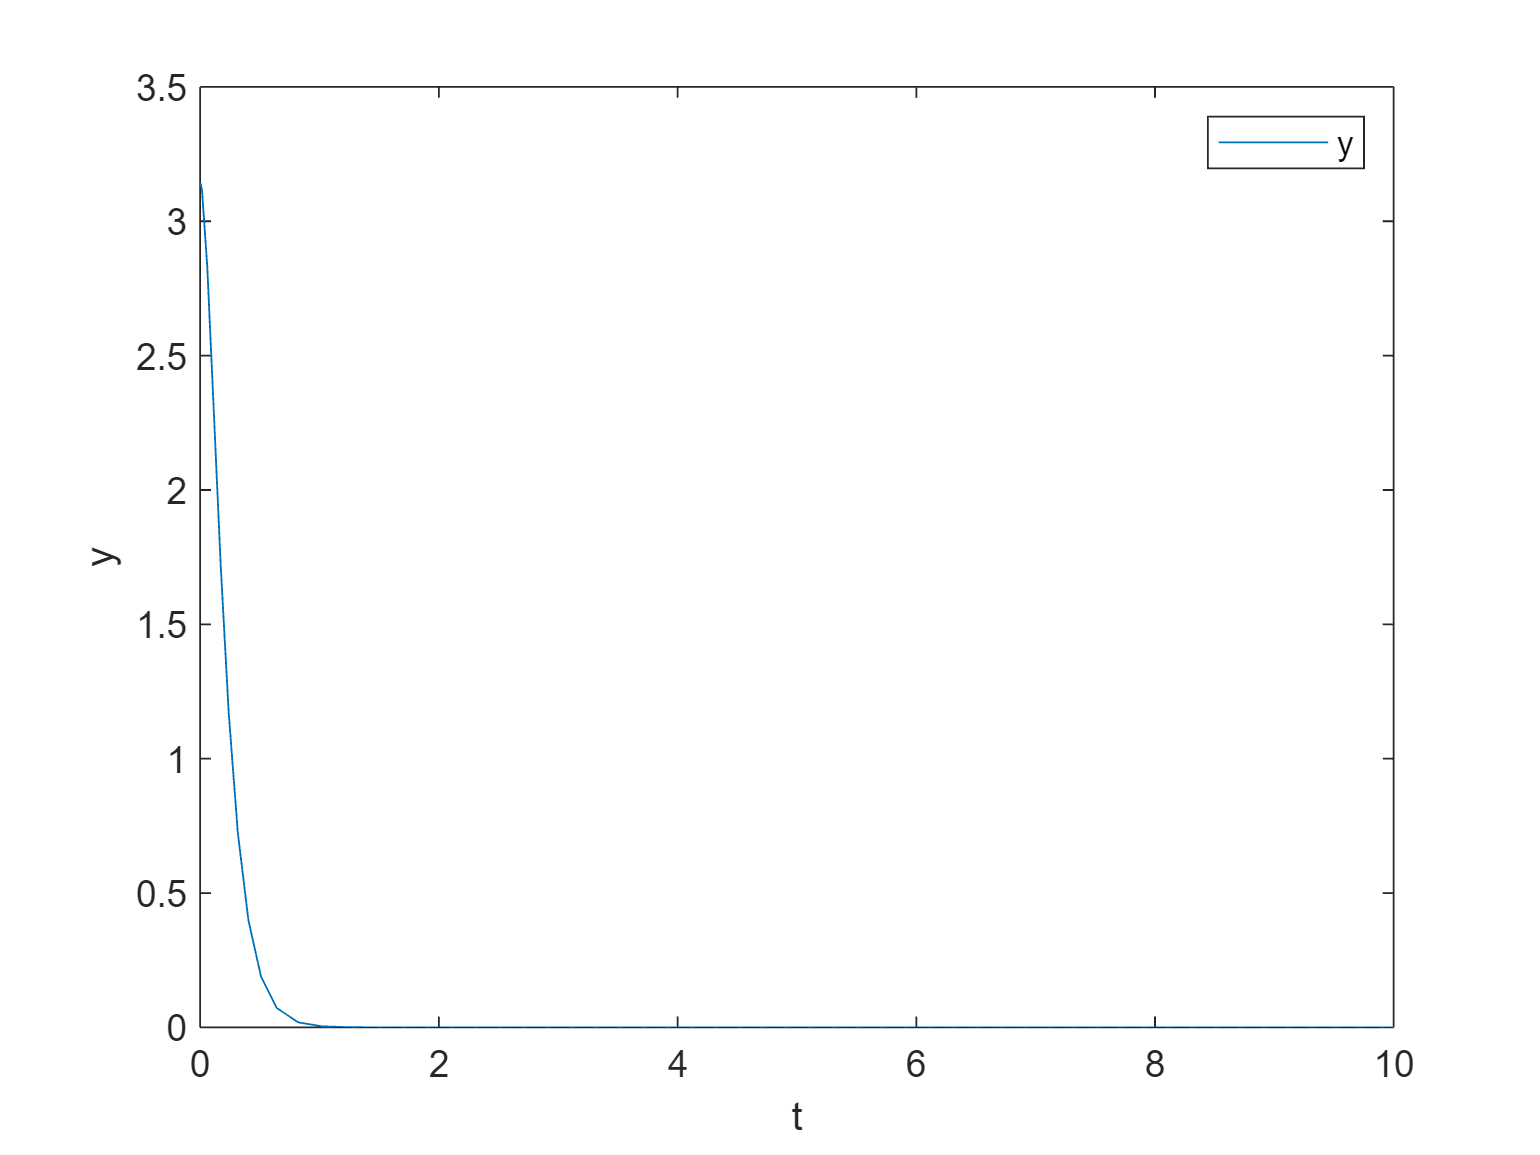

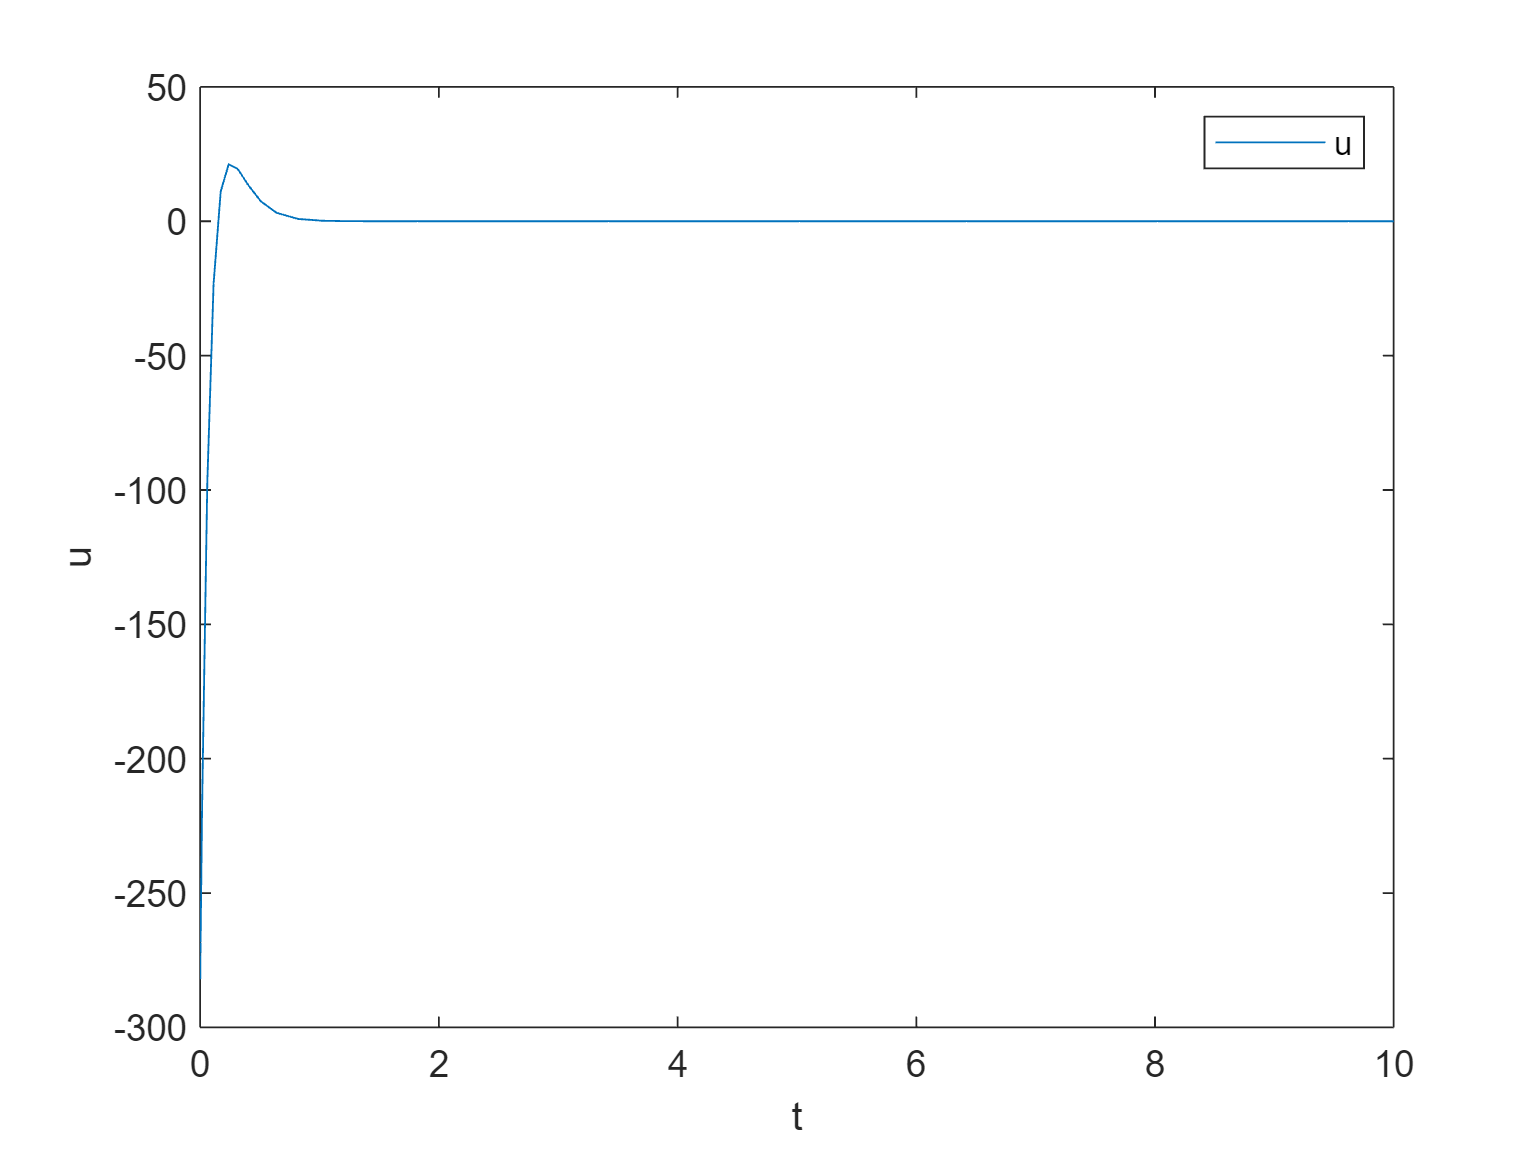

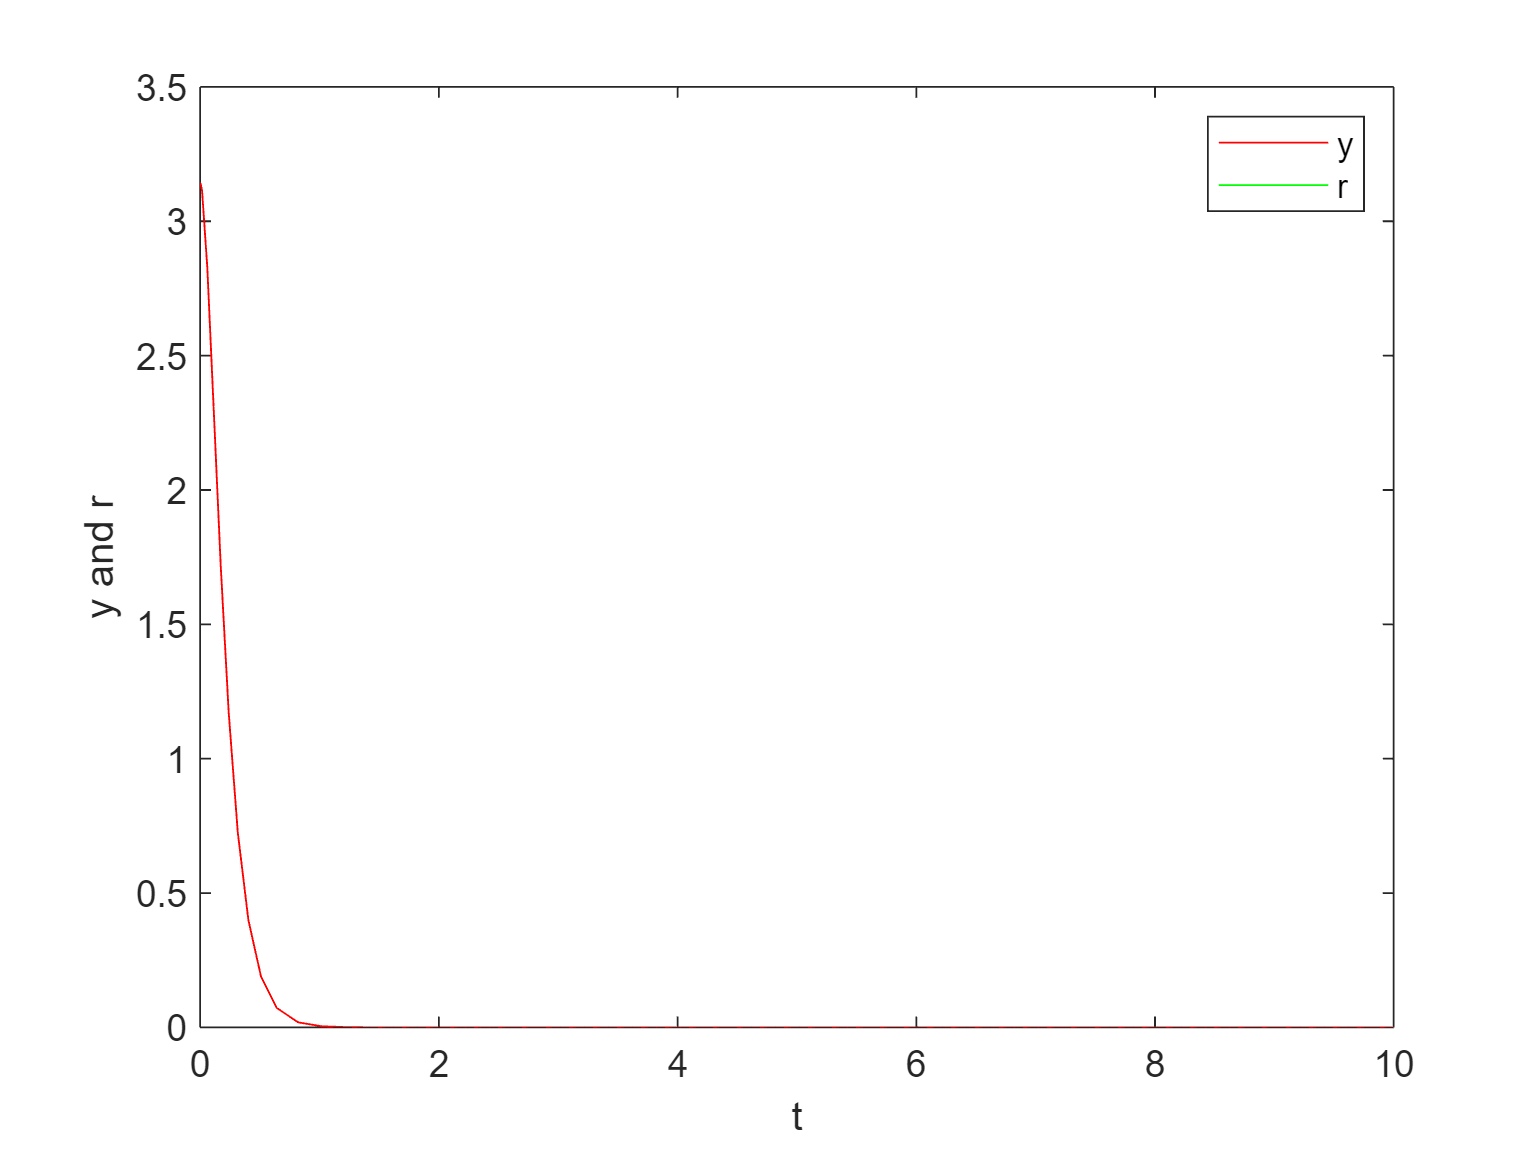

close all
rl = 0;
simOut = sim('PP_s_inv_L.slx', 'SimulationMode', 'normal');

% Chiamata alla funzione per visualizzare i risultati
plotSimulationResults(simOut,0);

Ovviamente nel caso lineare, stiamo cercando di inseguire come riferimento $0$, poichè il sistema è linearizzato in $\pi$, di conseguenza per analizzare la bontà del controllore è stato simulato il sistema a partire da condizioni iniziali diverse dal punto di equilibrio. L'analisi delle performance verrà effettuata per l'implementazione sul sistema non lineare.

## Test sul sistema non lineare

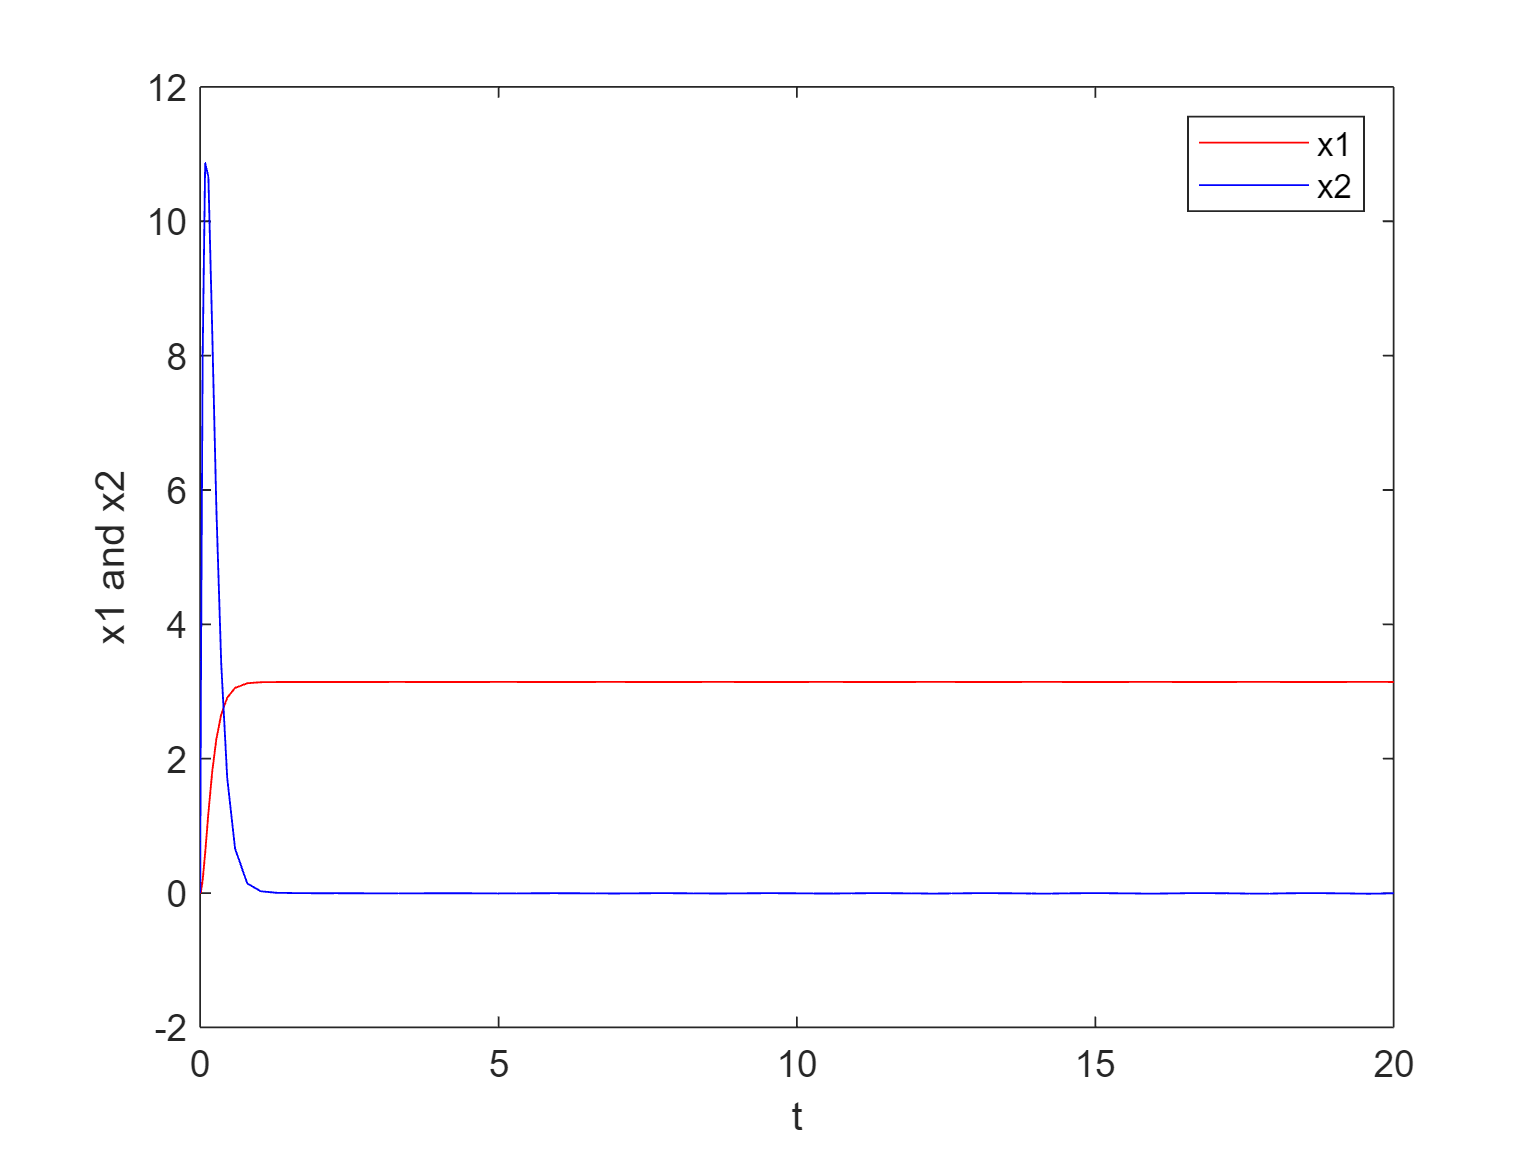

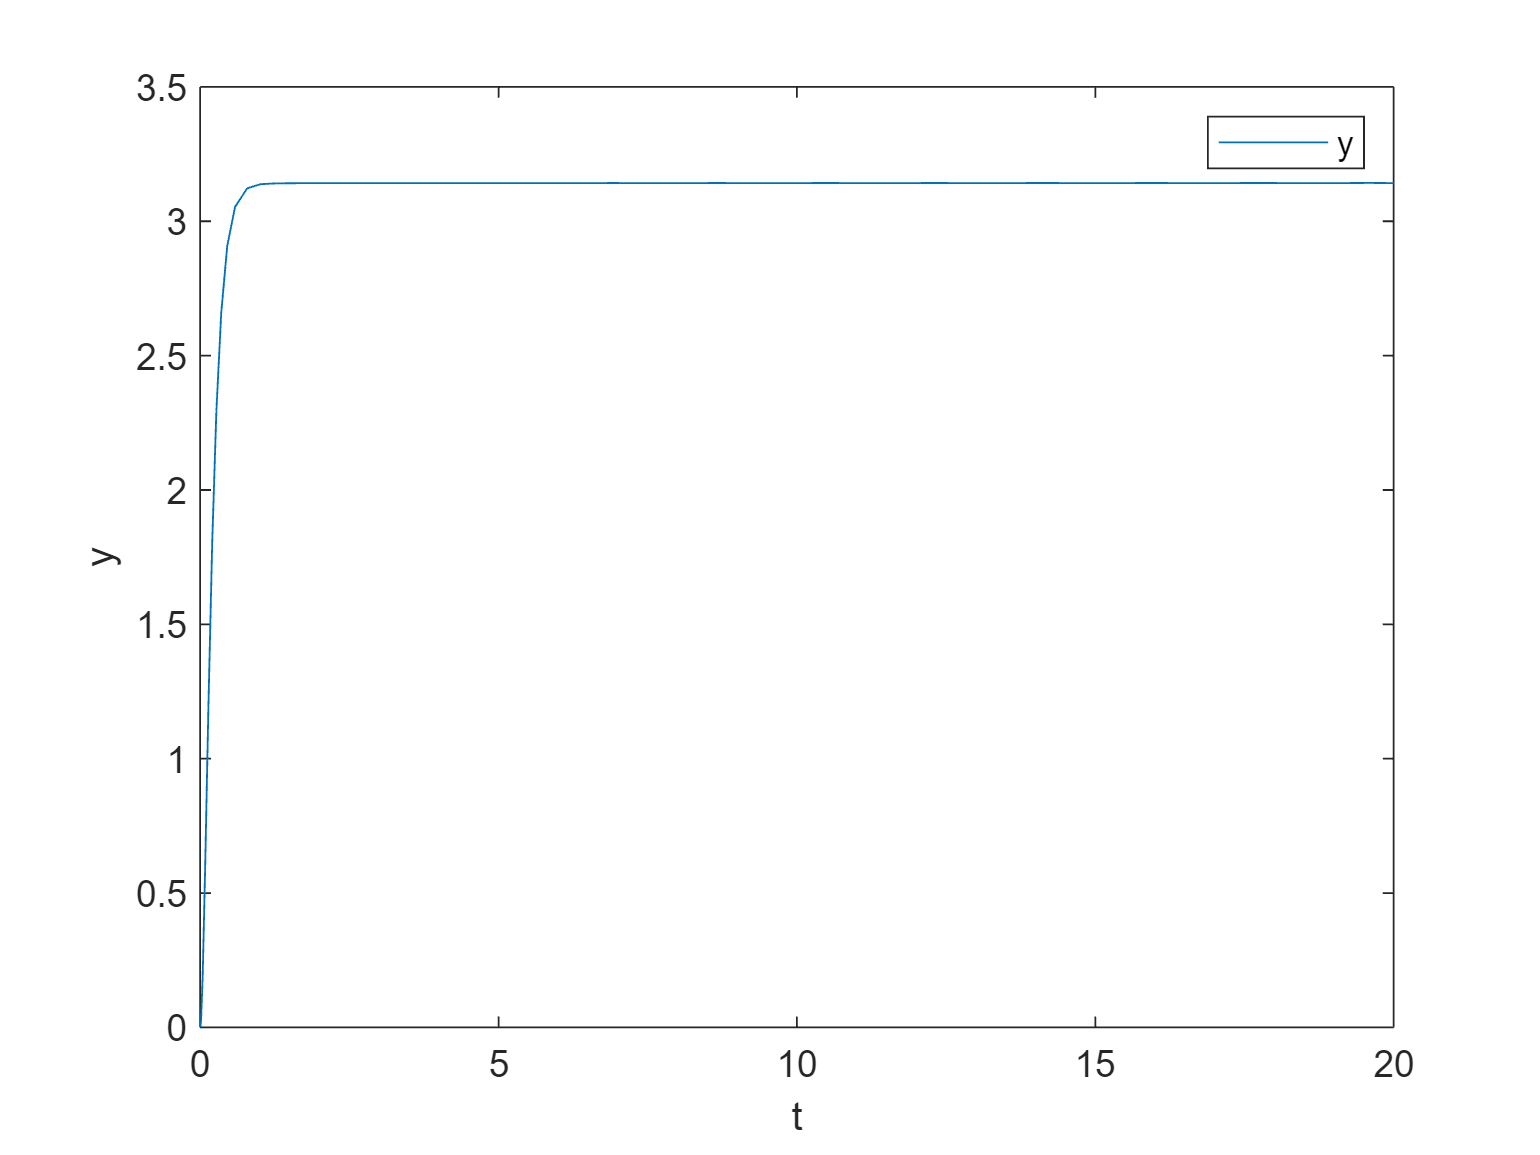

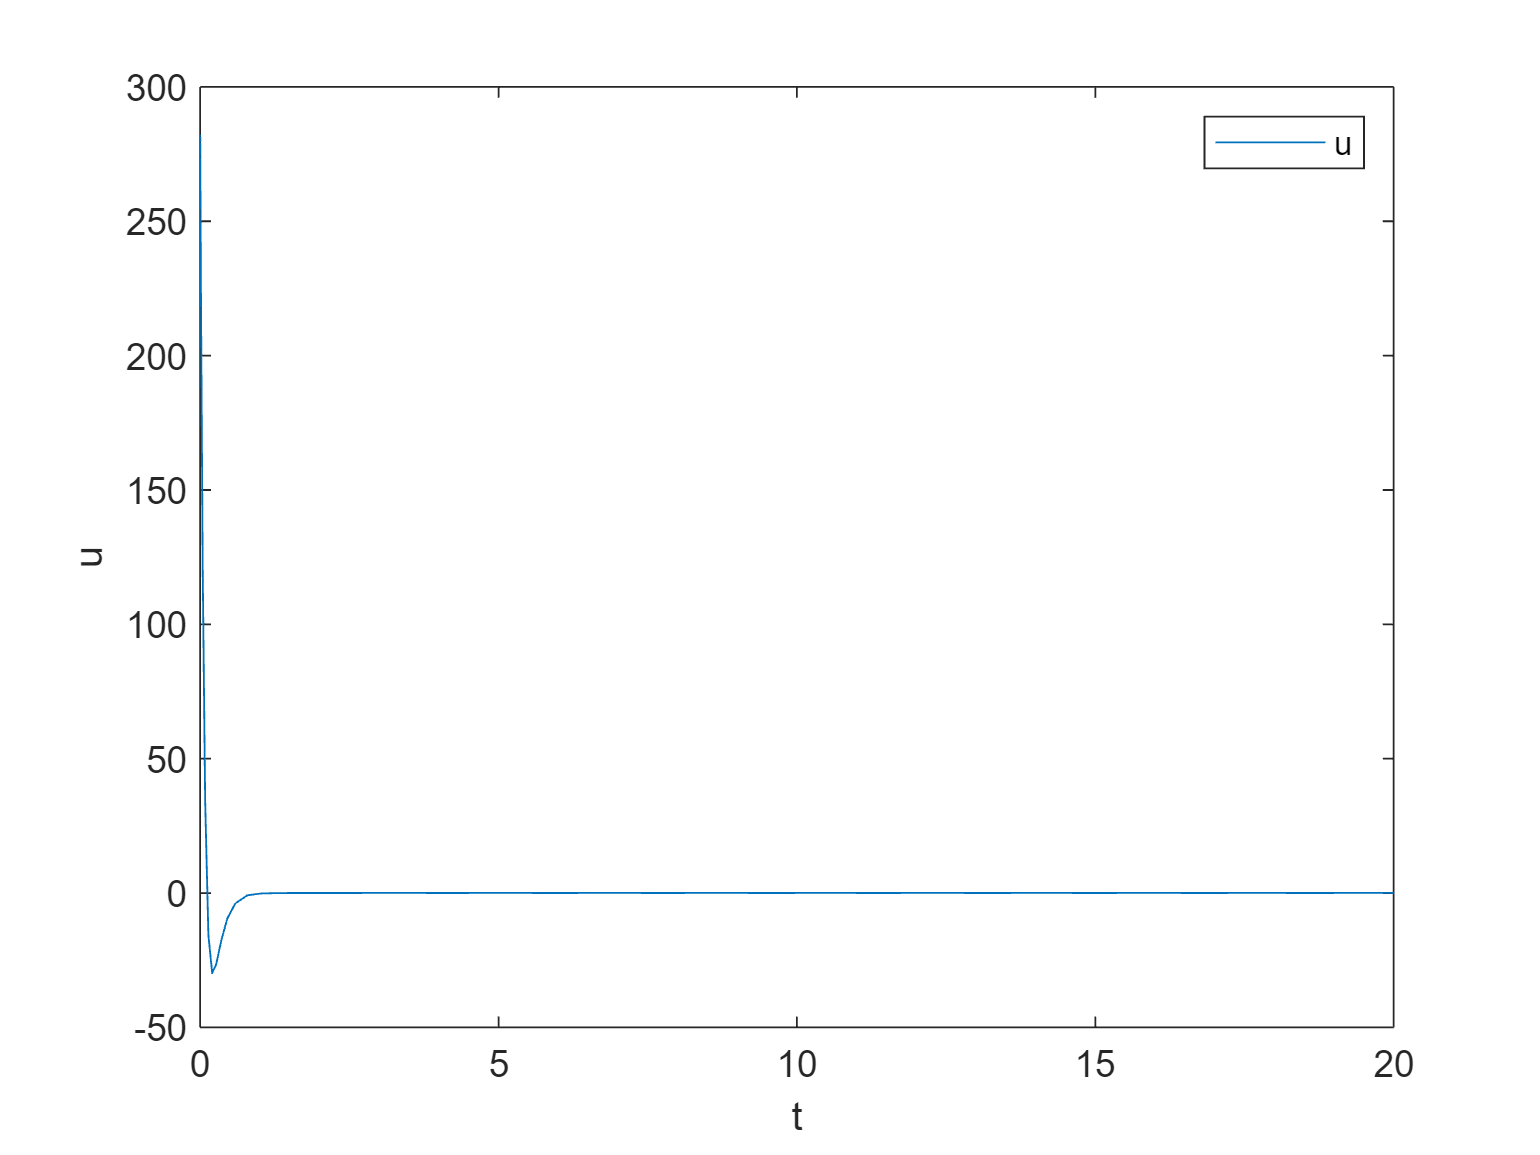

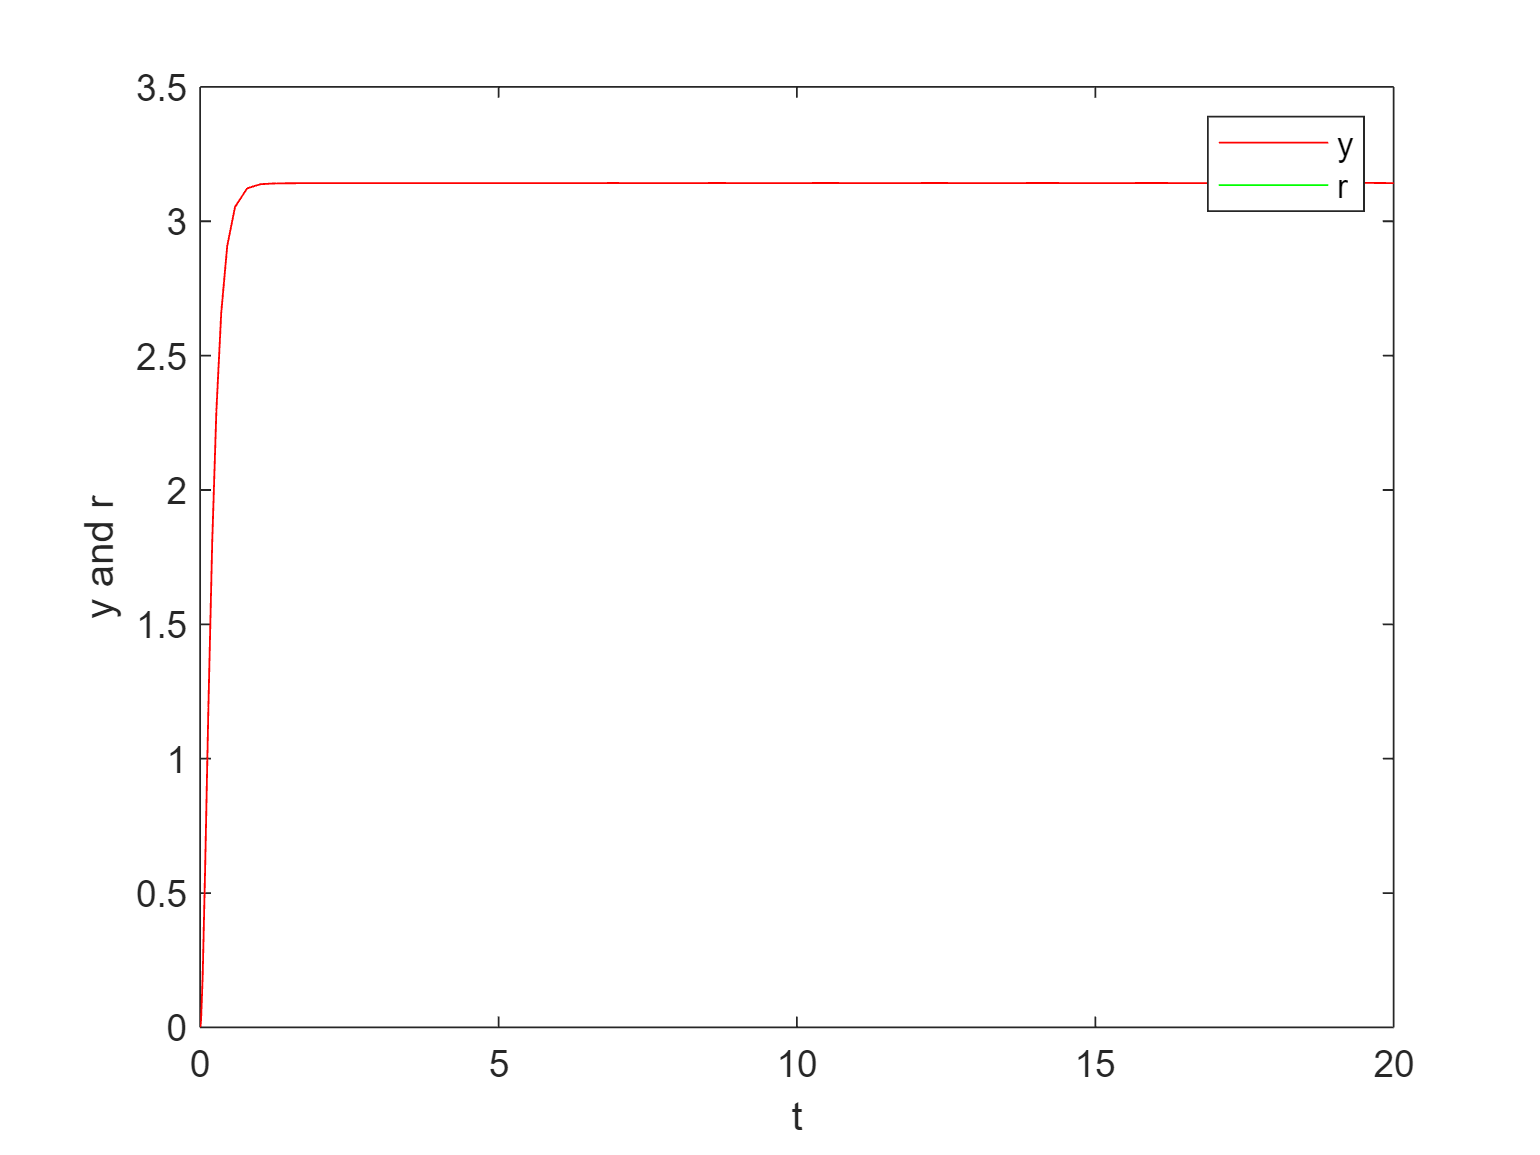

Step Information for the Output:
         RiseTime: 0.3662
    TransientTime: 0.6593
     SettlingTime: 0.6593
      SettlingMin: 2.9075
      SettlingMax: 3.1426
        Overshoot: 0.0272
       Undershoot: 0
             Peak: 3.1426
         PeakTime: 19.5859



close all
r=pi;
simOut = sim('PP_s_inv_NL.slx', 'SimulationMode', 'normal');

plotSimulationResults(simOut,1);

Dall'analisi delle performance sul non lineare si può apprezzare come, a differenza del controllore fornito dalla traccia, il sistema raggiunge il punto di equilibrio, molto più lentamente rispetto a quanto avveniva in precedenza, così come il tempo di assestamento del sistema risulta maggiore, ma con uno sforzo di controllo molto limitato e consono alla realtà fisica in cui ci si è ristretti. Anche la sovraelongazione è contenuta se non quasi inesistente. A primo impatto le migliorie fornite da questo controllore sono abbastanza per considerarlo migliore a quello del caso precedente, considerando i limiti autoimposti. Per definire delle prestazioni dinamiche desiderate e utilizzare la funzione place, dovremmo scegliere i poli da piazzare che corrispondono a quelli del polinomio caratteristico con prestazioni dinamiche desiderate, a tal punto si è deciso di usare direttamente l'equipollenza dei polinomi.

## Pole placement tramite equipollenza dei polinomi

Analogamente a quanto descritto in precedenza, proseguiamo con il piazzamento degli autovalori del sistema a ciclo chiuso per garantire stabilità e performance adeguate. Dato che il sistema è un sistema del secondo ordine possiamo considerare il polinomio caratteristico del sistema a ciclo chiuso, ovvero della matrice $[A-BK]=\left[\begin{array}{c} 0-0 & 1-0 \\ 9.81-k_1 & -0.1-k_2 \end{array}\right]$:

$sI-A+BK=\left[\begin{array}{c} s & -1 \\ -9.81+k_1 & s+0.1+k_2 \end{array}\right]$ ottenendo:


$$s^2+0.1s+k_2s-9.81+k_1=s^2+(0.1+k_2)s+(k_1-9.81)$$


A questo punto si ottiene che


$$k_1=\omega_o^2+9.81 \\ k_2=2\omega_o\zeta_o-0.1$$


L'analisi successiva è basata sulle proprietà di risposta al gradino di un sistema del secondo ordine in base ai parametri di pulsazione naturale $\omega_0
$ e del coefficiente di smorzamento $\zeta_0$:

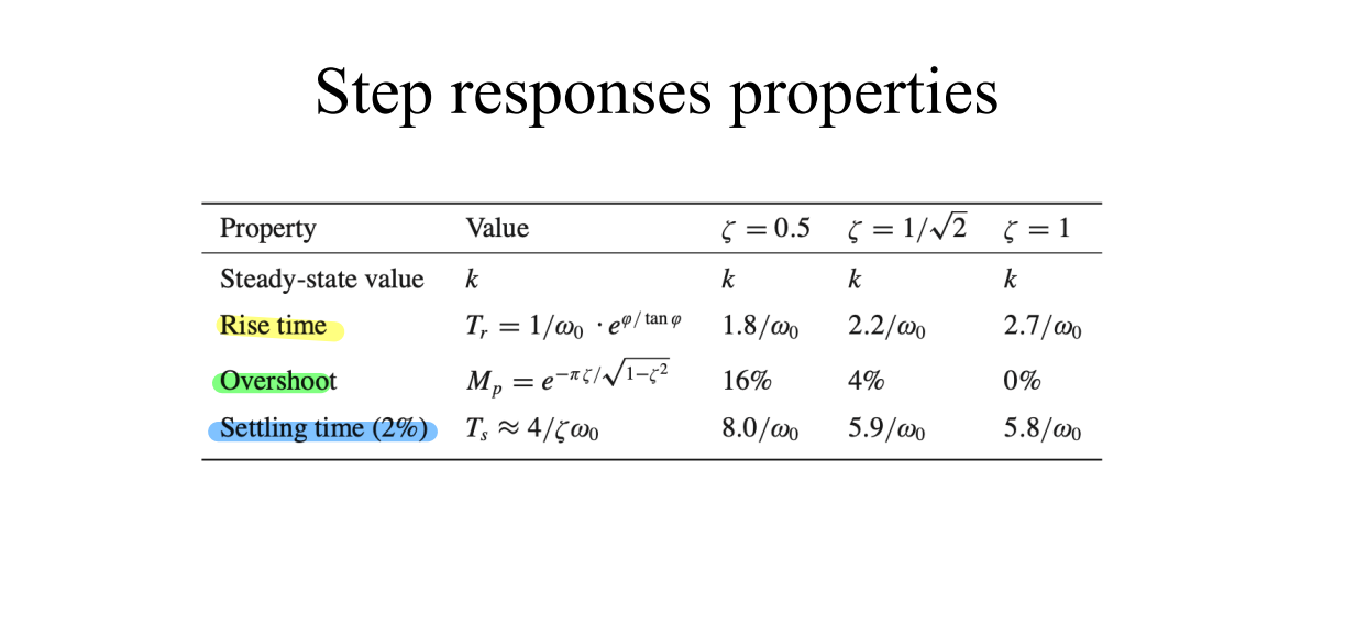

imshow(imread("img/step_responses_properties.png"))

Anche in questo caso sono stati effettuati numerosi esperimenti, con prestazioni del sistema differenti, ma è stato riportato un unico esperimento che rappresenta la migliore configurazione trovata per il sistema in questione.

Dall'analisi del controllore $v_0$ alcune criticità riportate erano la sovraelongazione esagerata e le numerose oscillazioni, a tal proposito si è tentato di ridurre notevolmente la sovraelongazione, ma mantenendo un tempo di salita e assestamento molto bassi, secondo quanto descritto dalla tabella:

zita = 1/sqrt(2);
w = 2.2/0.25;

%caso estremo umax=+inf
%zita = 1
%w = 2.7/0.001

k1=w^2+9.81;
k2=2*zita*w-0.1;
K=[k1 k2];
kr=-1/(C*inv(A-B*K)*B);

## Test sul sistema lineare

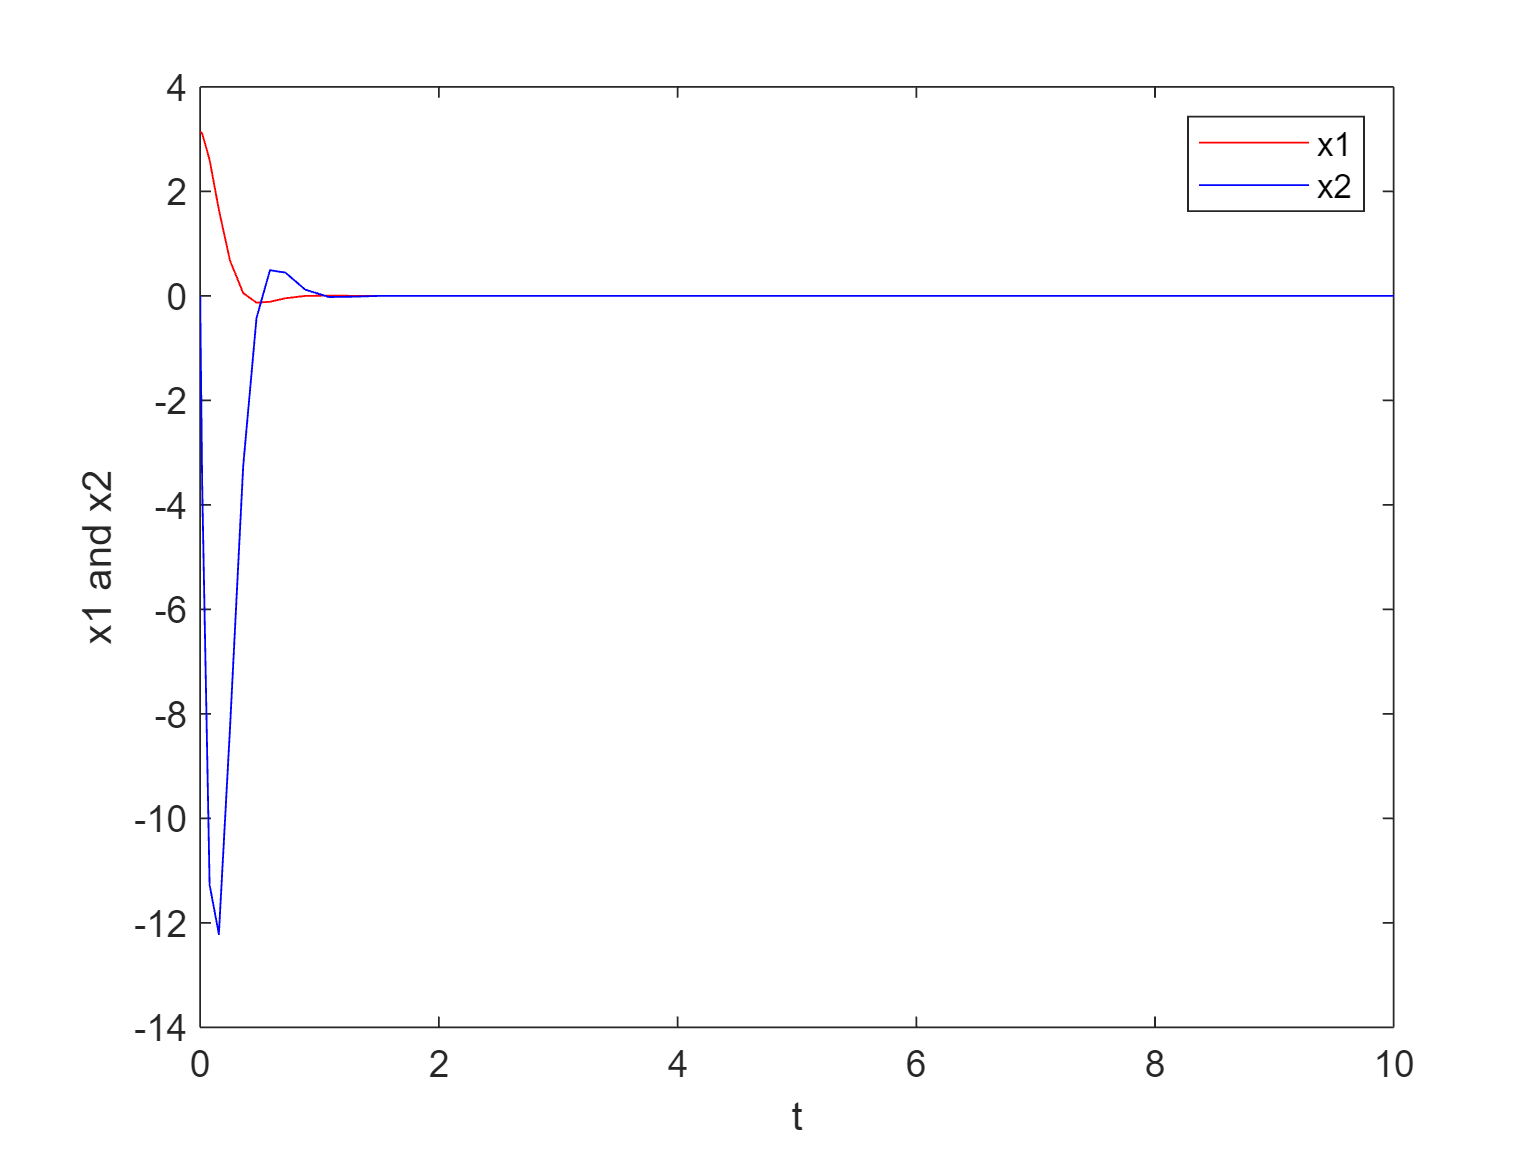

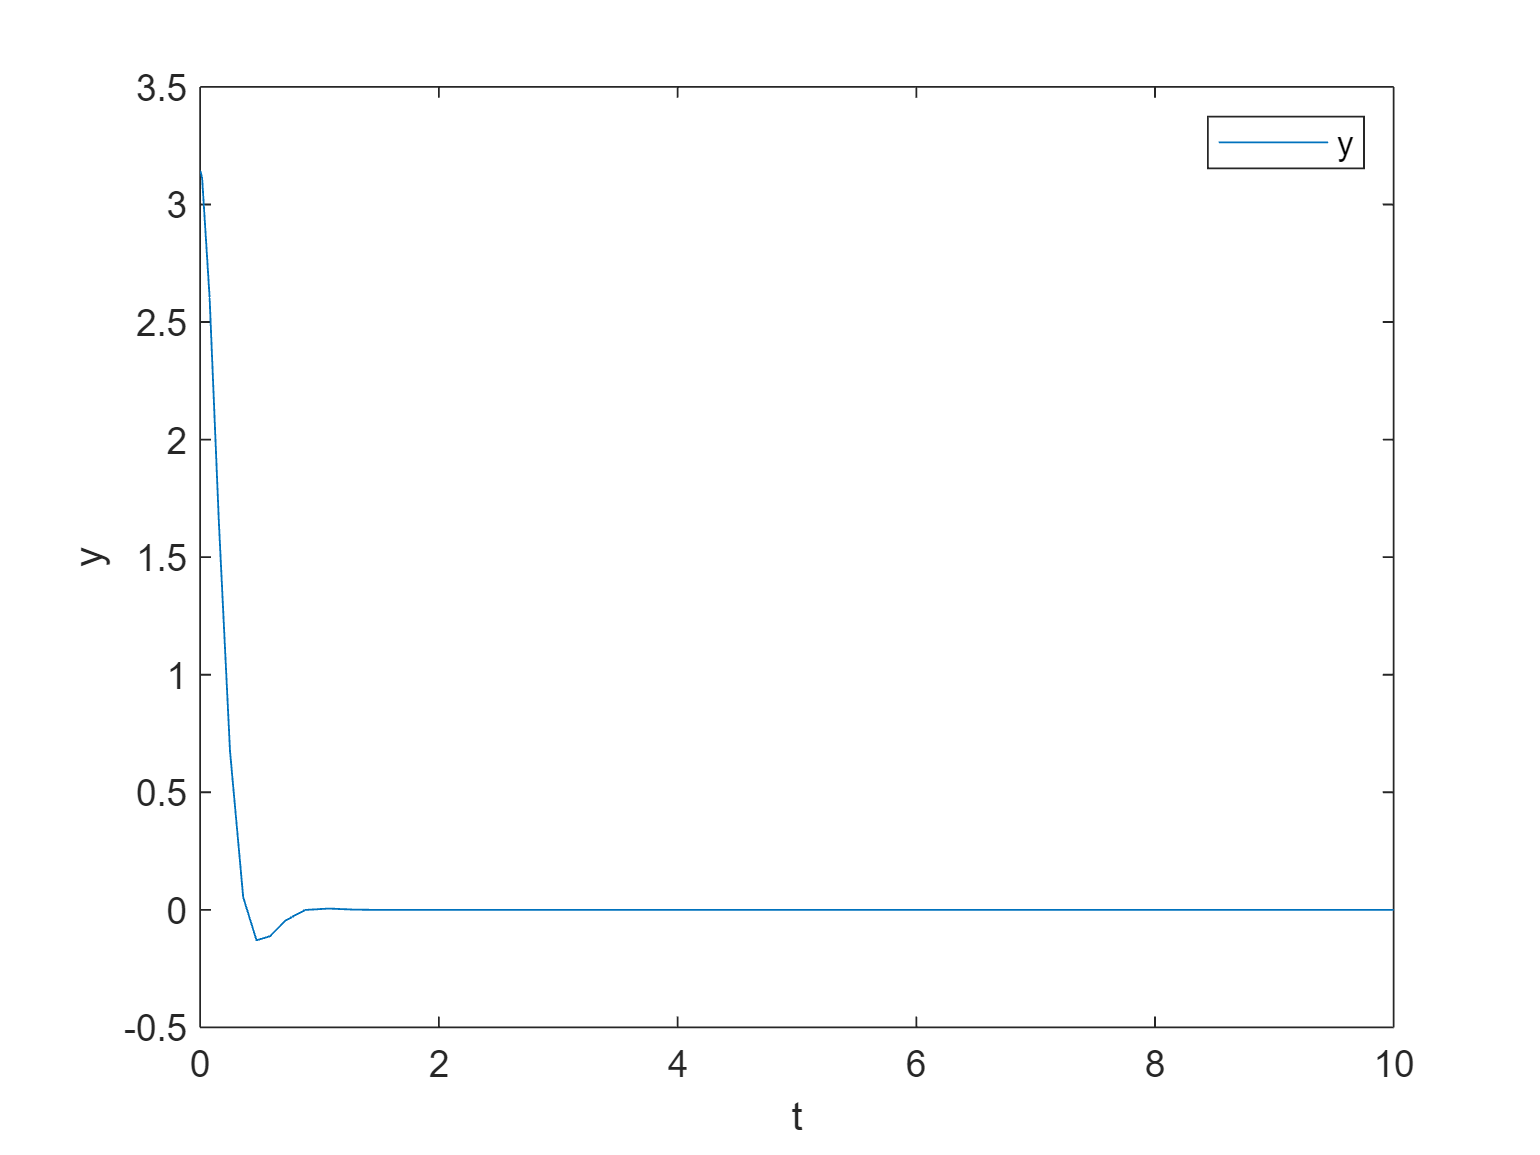

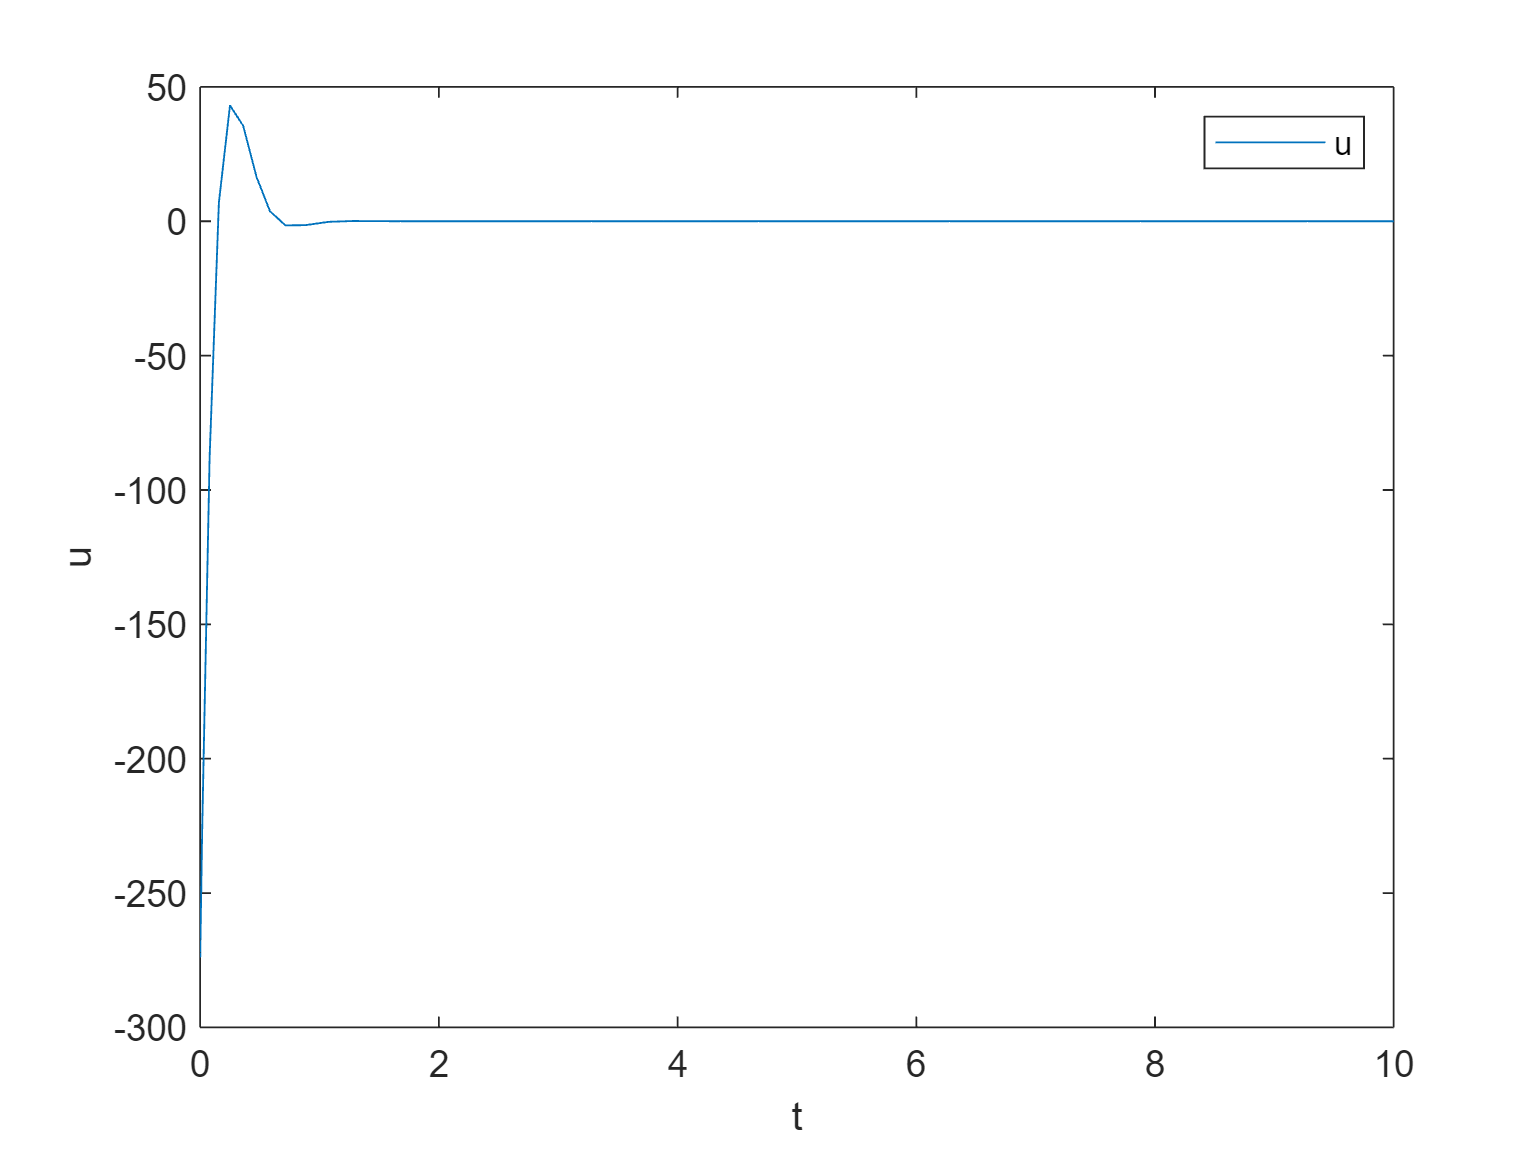

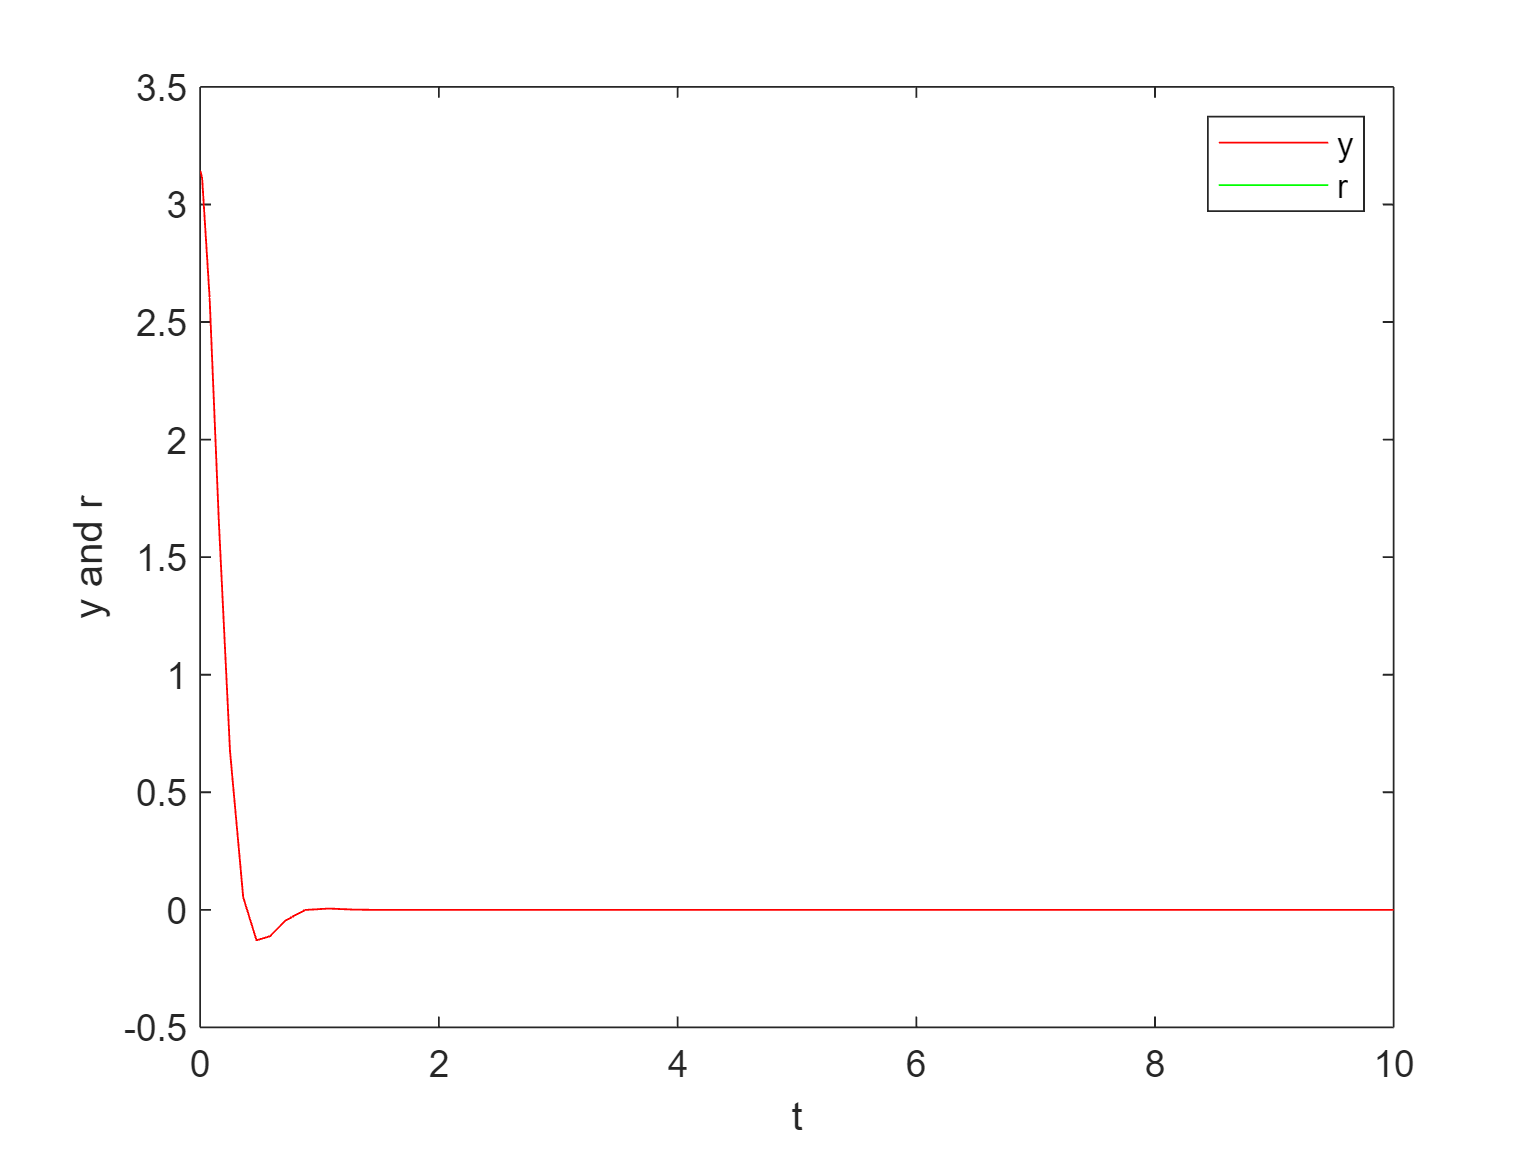

close all
rl = 0;
simOut = sim('PP_s_inv_L.slx', 'SimulationMode', 'normal');

% Chiamata alla funzione per visualizzare i risultati
plotSimulationResults(simOut,0);

Dall'analisi della risposta del sistema nel caso lineare, nonostante un pò di sottoelongazione, il sistema raggiunge l'obiettivo, di conseguenza è stata verificata l'efficacia e valutate le prestazioni nel caso non lineare.

## Test sul sistema vero e proprio

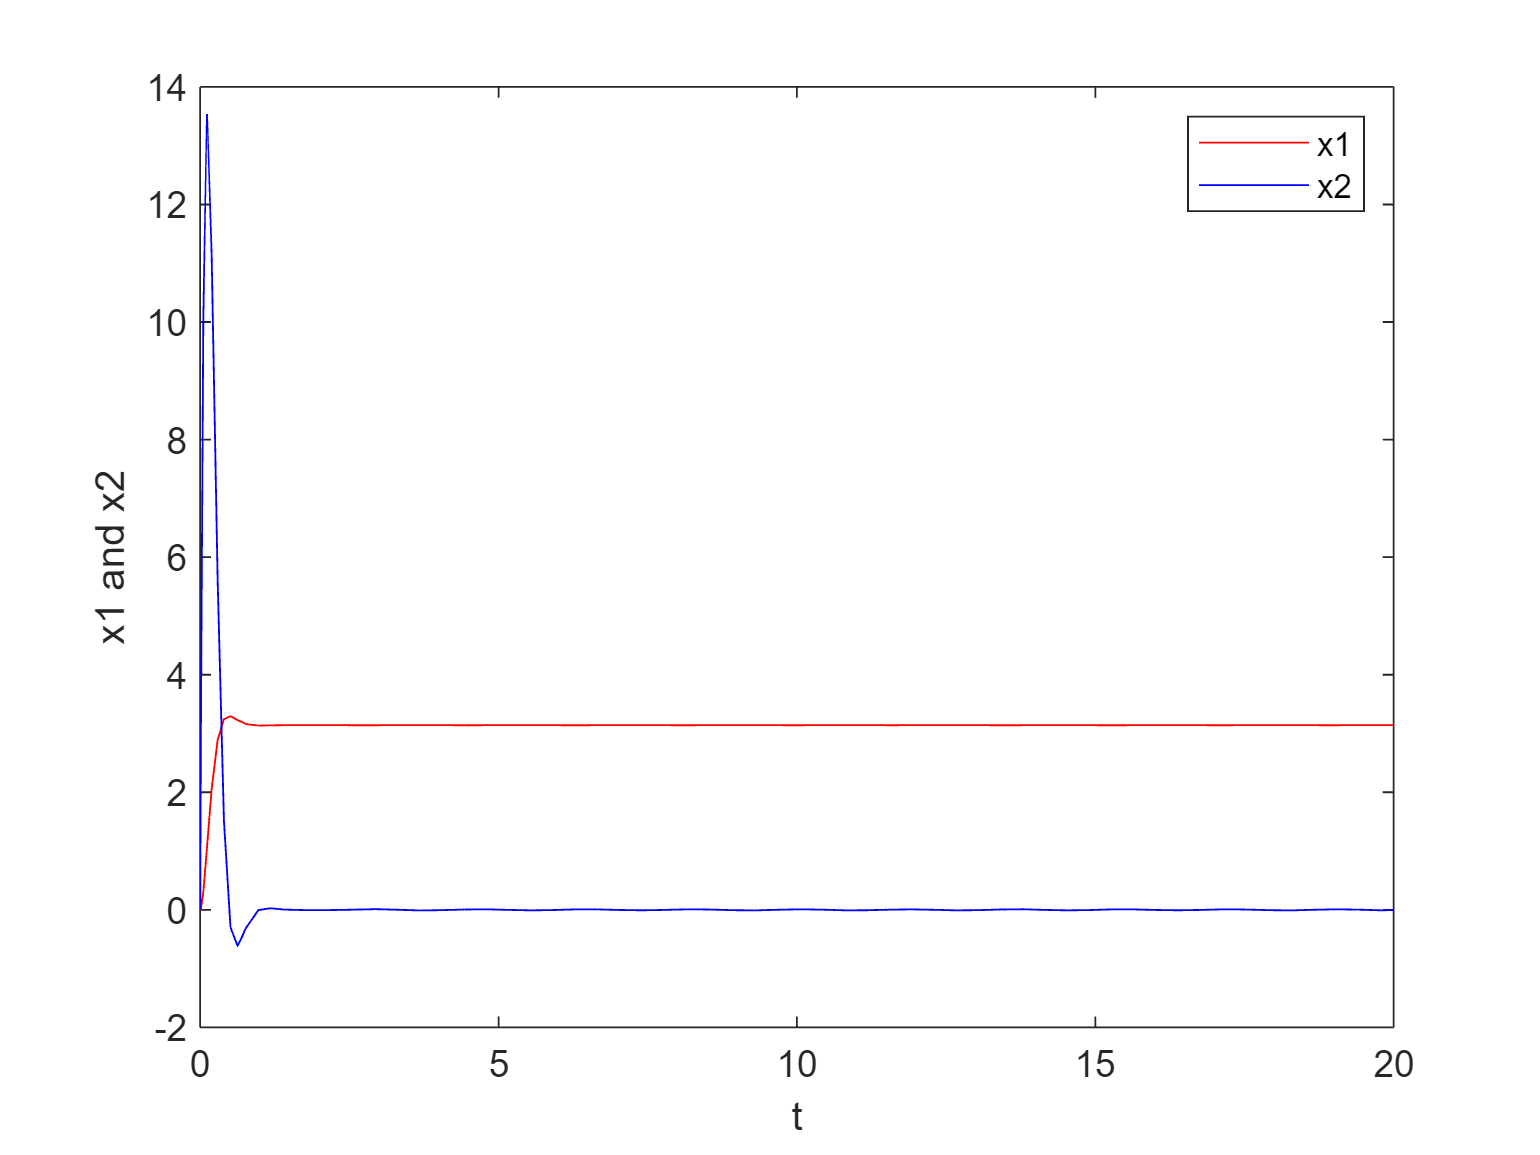

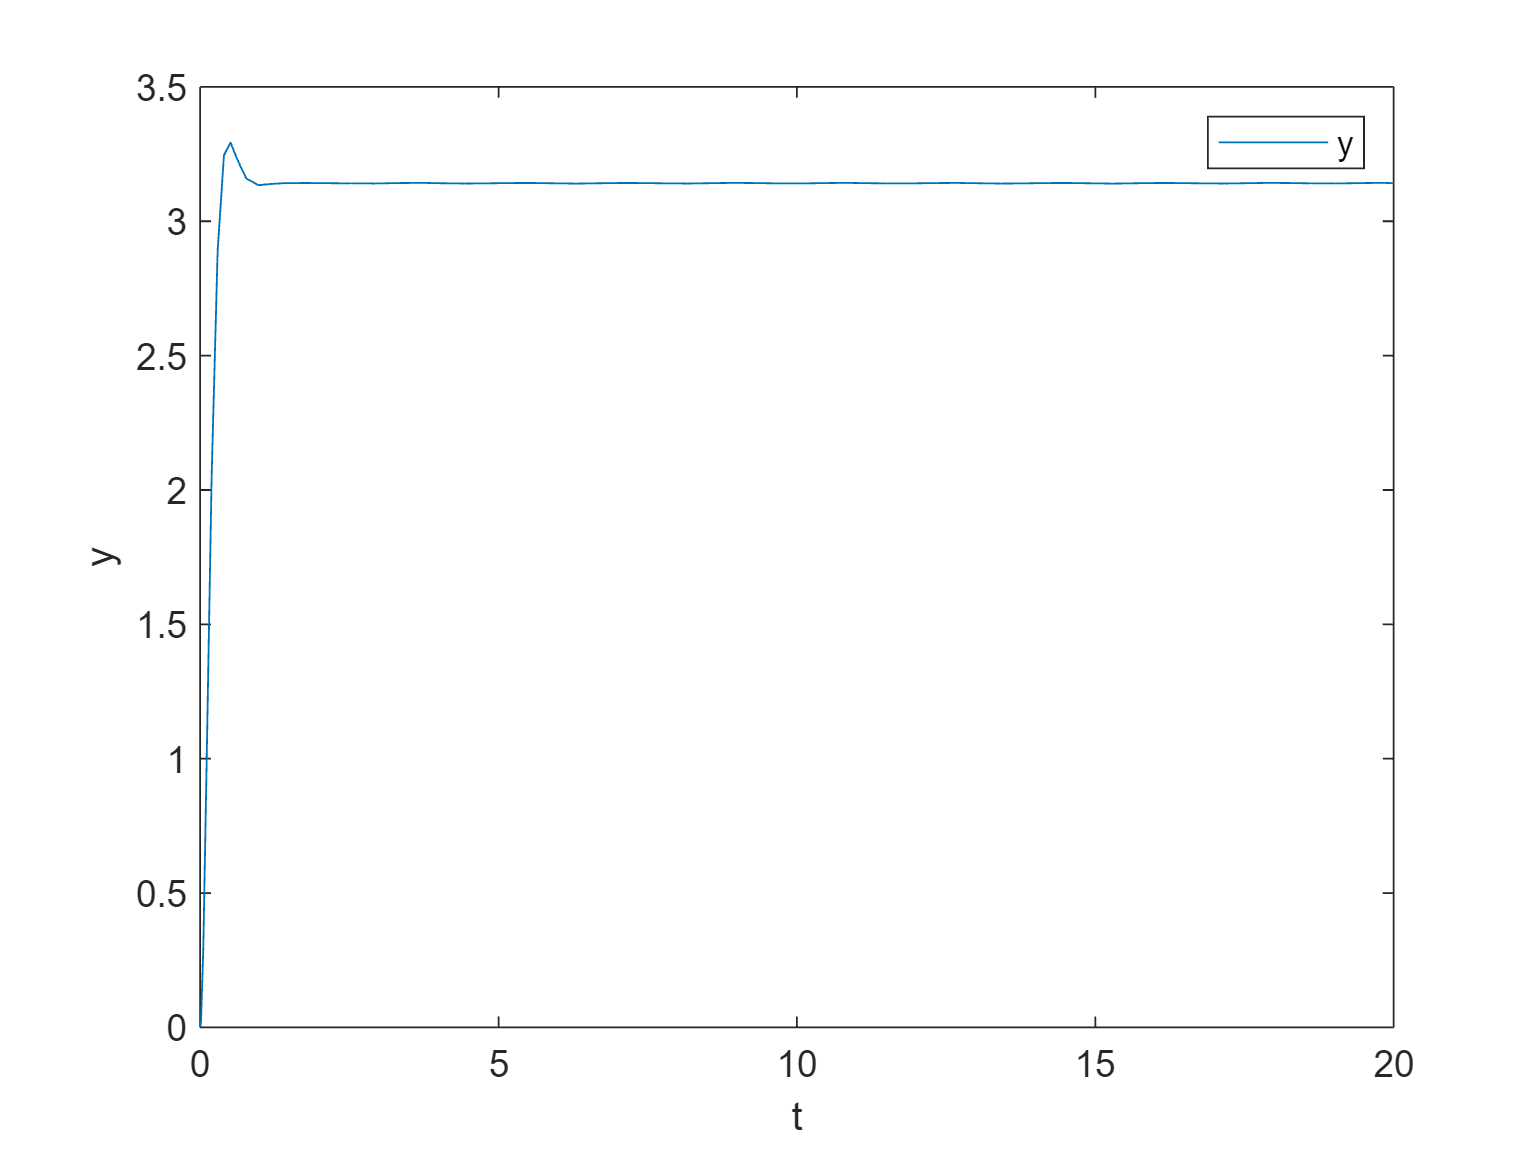

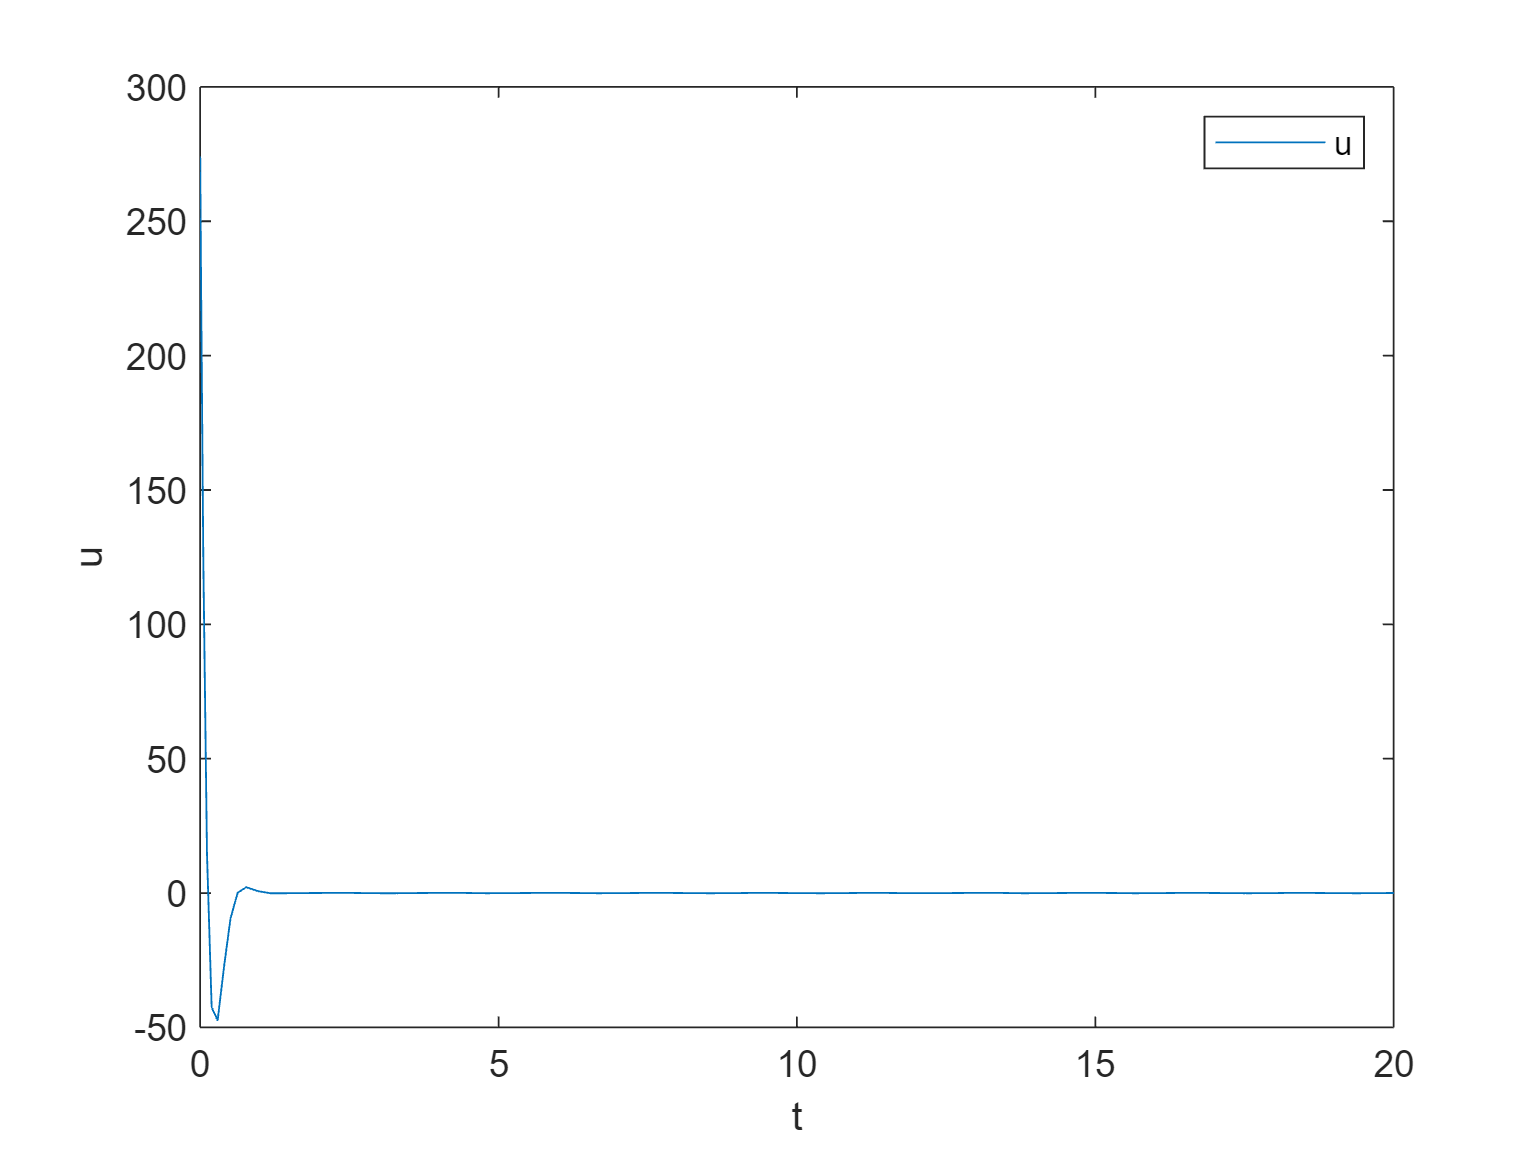

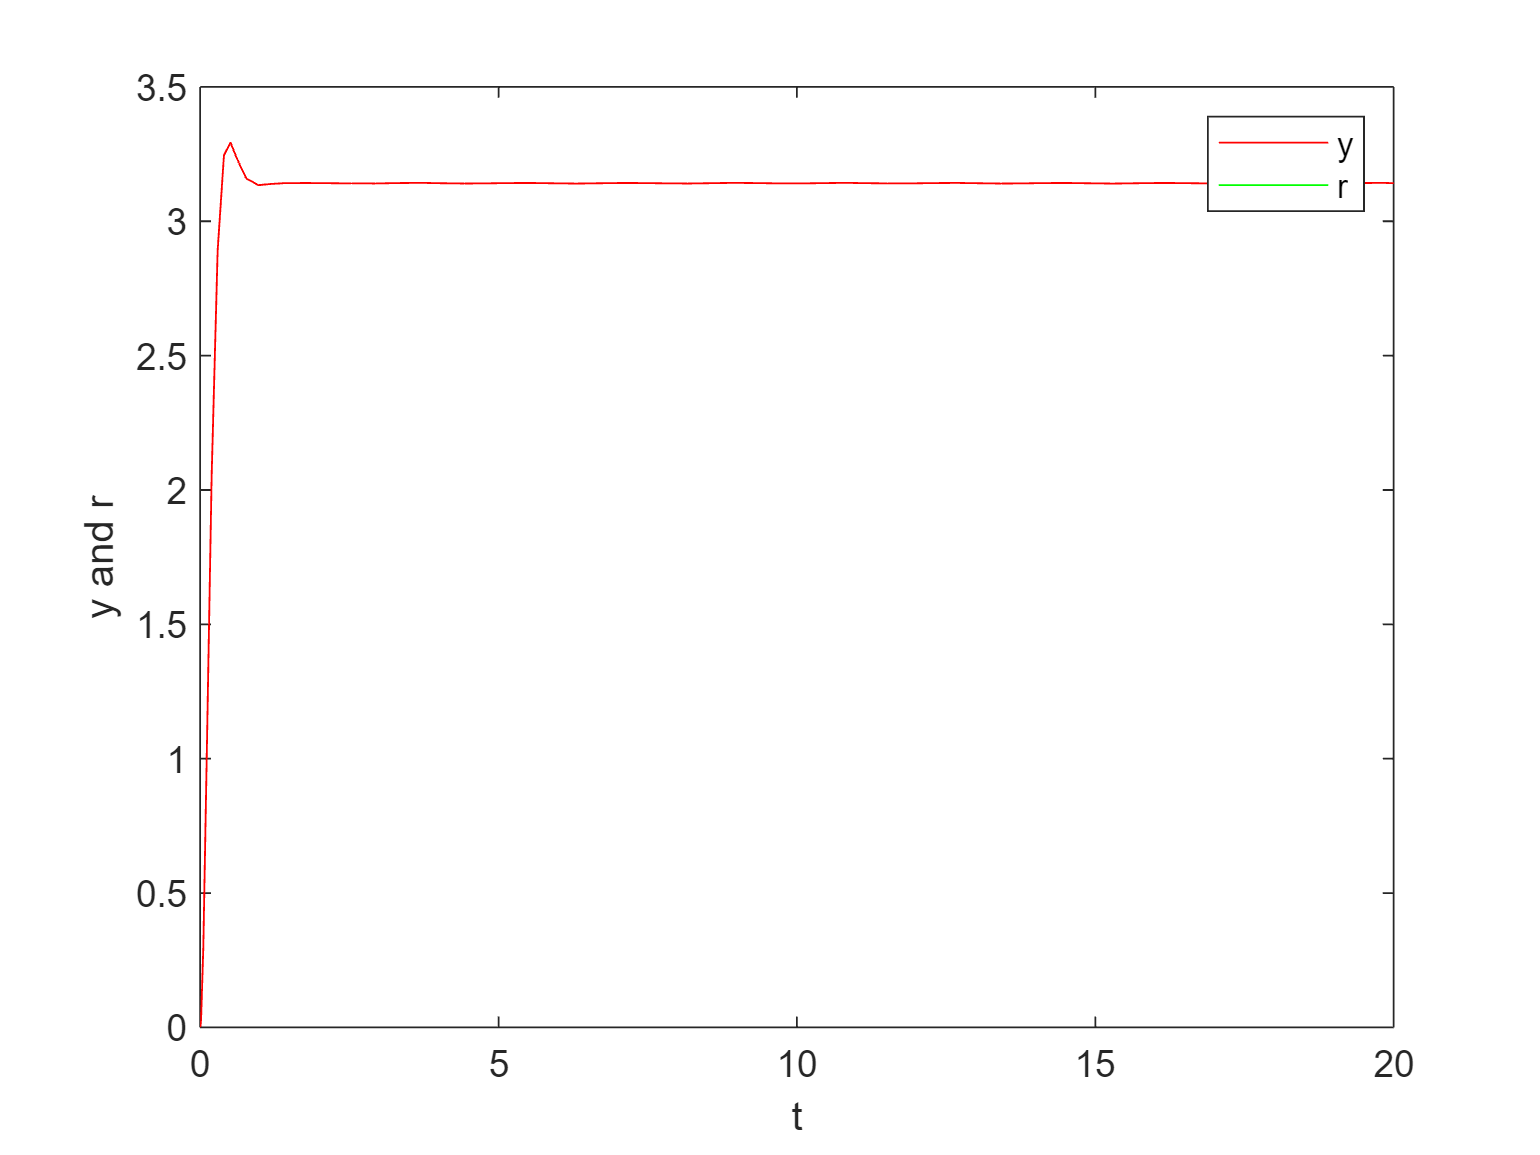

Step Information for the Output:
         RiseTime: 0.2312
    TransientTime: 0.6759
     SettlingTime: 0.6759
      SettlingMin: 2.8913
      SettlingMax: 3.2928
        Overshoot: 4.8085
       Undershoot: 0
             Peak: 3.2928
         PeakTime: 0.5074



close all
r=pi;
simOut = sim('PP_s_inv_NL.slx', 'SimulationMode', 'normal');

% Chiamata alla funzione per visualizzare i risultati
plotSimulationResults(simOut,1);

Dall'analisi del sistema notiamo come, a differenza del caso precedente, il tempo di salita è molto più basso a discapito di una leggera sovraelongazione che però porta il sistema a raggiungere l'obiettivo più velocemente. In questo caso stiamo richiedendo, secondo la tabella, una sovraelongazione di massimo $4\%$ ed è, praticamente, rispettata, così come un tempo di assestamento pari a $0.67s
$ ed un tempo di salita pari a $0.25s$. Entrambi i controllori appena proposti hanno degli aspetti migliorativi rispetto al caso proposto da traccia, come una sovraelongazione sostenuta, così come l'azione di controllo, a discapito di performance meno esagerate, ma di gran lunga più feasible.

## **Linear Quadratic Regulator (LQR)**

Nel caso dell'implementazione di un controllore tramite LQR, l'obiettivo sta nel regolare il sistema intorno ad un punto desiderato, nel nostro caso, per il sistema linearizzato si tratta di rimanere intorno al punto di equilibrio intorno al quale è stato linearizzato. Tale regolarizzazione avviene facendo riferimento ad un task di minimizzazione e per rendere tale task quanto più semplice possibile, ovvero avere il minimo in $0$ piuttosto che in un altro valore, ha senso costruire il controllore a partire dal sistema linearizzato intorno al punto di equilibrio $x_e = [\pi,0]$. Procedere ad una linearizzazione di questo tipo è equivalente a definire la trasformazione delle variabili di stato e di ingresso di controllo, rispettivamente:


$$z = x-x_e\\v=u-u_e$$


ed utilizzarla per rappresentare il sistema. A questo punto, la procedura di minimizzazione per il controllore LQR avrà punto minimo in $0
$, il che implica che il controllore sarà del tipo $v = -Kz$. Tale minimizzazione è equivalente, nel sistema non lineare, al raggiungimento del riferimento $r = \pi
$.

Sempre facendo riferimento al sistema trasformato, si definiscono le matrici $Q_z \spaceQ_v$ che entrano in gioco nella funzione di costo da minimizzare, infatti l'indice di performance $\tilde J = \int_0^T z^TQ_zz + v^TQ_vv \; dt$ dipende da entrambe queste matrici, la minimizzazione sarà un problema del tipo         $min_{v(t)}\tilde J \\ s.t. \quad \ \dot z=Az+Bv,\ \ \ z_o \text{ dato}$

La funzione è quadratica sia nello stato che nell'ingresso di controllo e le due matrici devono essere definite positive per garantire l'esistenza di una soluzione nella pratica. Ragionando in termini scalari, scegliere le due matrici implica avere la sensibilità di individuare quali stati o azioni di controllo sia necessario minimizzare per il problema. Nel nostro caso un coefficiente maggiore per lo stato $x_1
$ implica il raggiungimento dell'obiettivo, mentre un coefficiente maggiore per l'azione di controllo $u$ spinge la funzione a garantire un azione di controllo contenuta. Per quanto riguarda $x_2$ l'aumento del coefficiente diminuisce la velocità massima del sistema. Lo schema di riferimento simulink è il seguente:

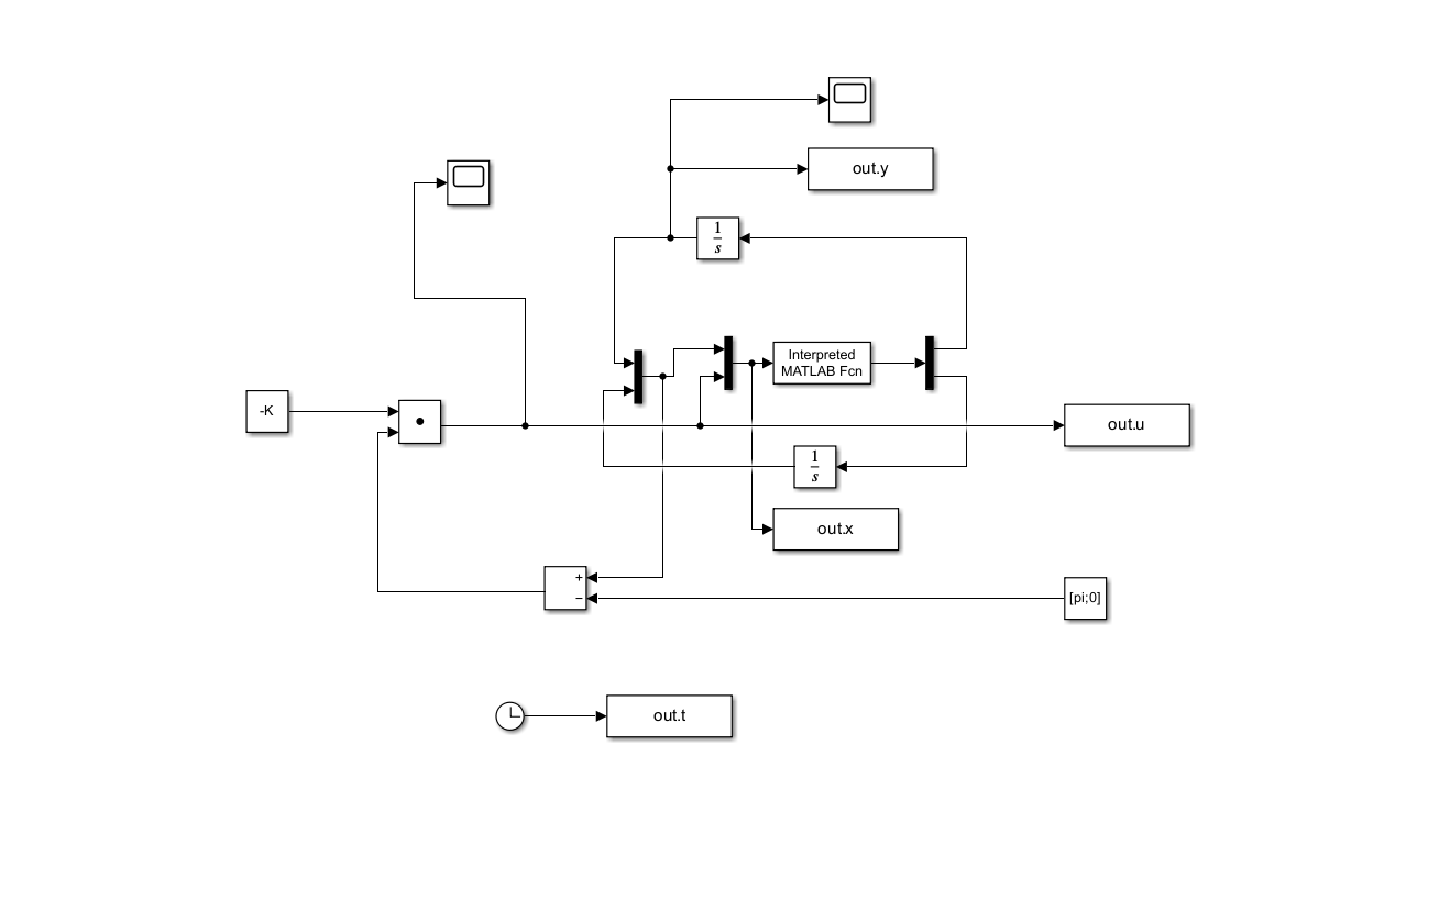

imshow(imread("img/lqr_scheme.png"));

Nel nostro caso l'obiettivo era rappresentato dal raggiungere il punto $(\pi,0)
$, ma mantenere un azione di controllo contenuta, di conseguenza, dopo attenta taratura dei valori si è ottenuto:

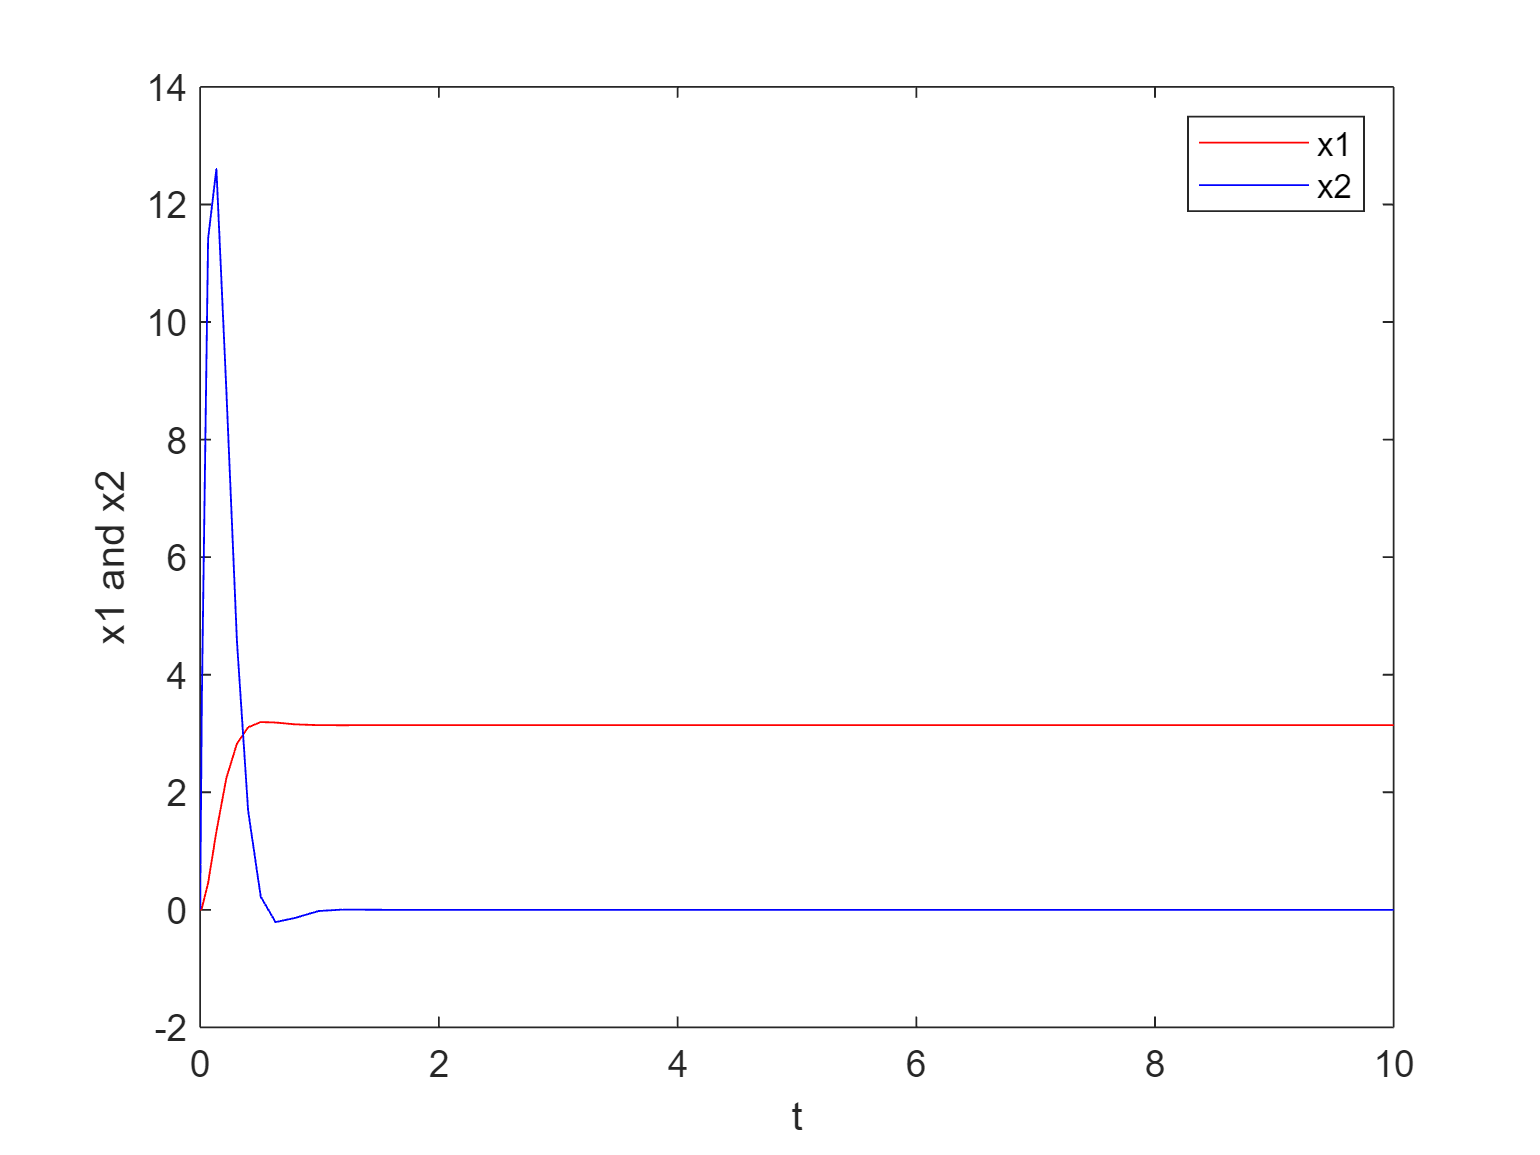

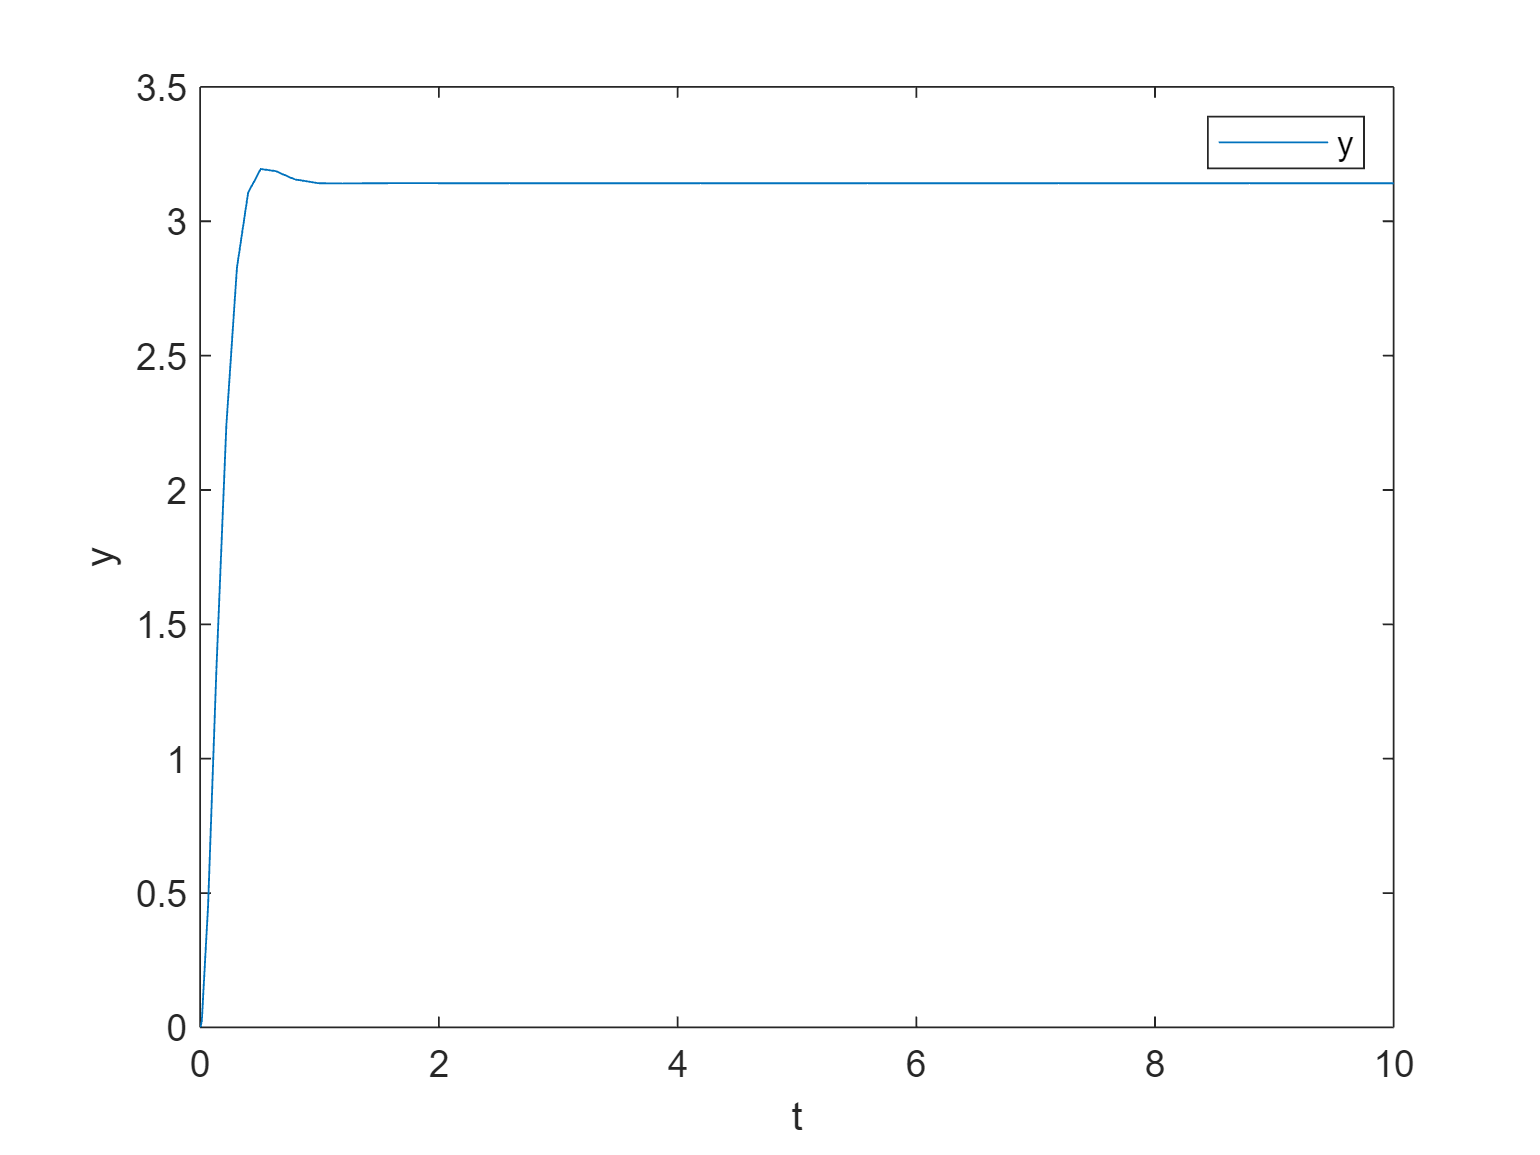

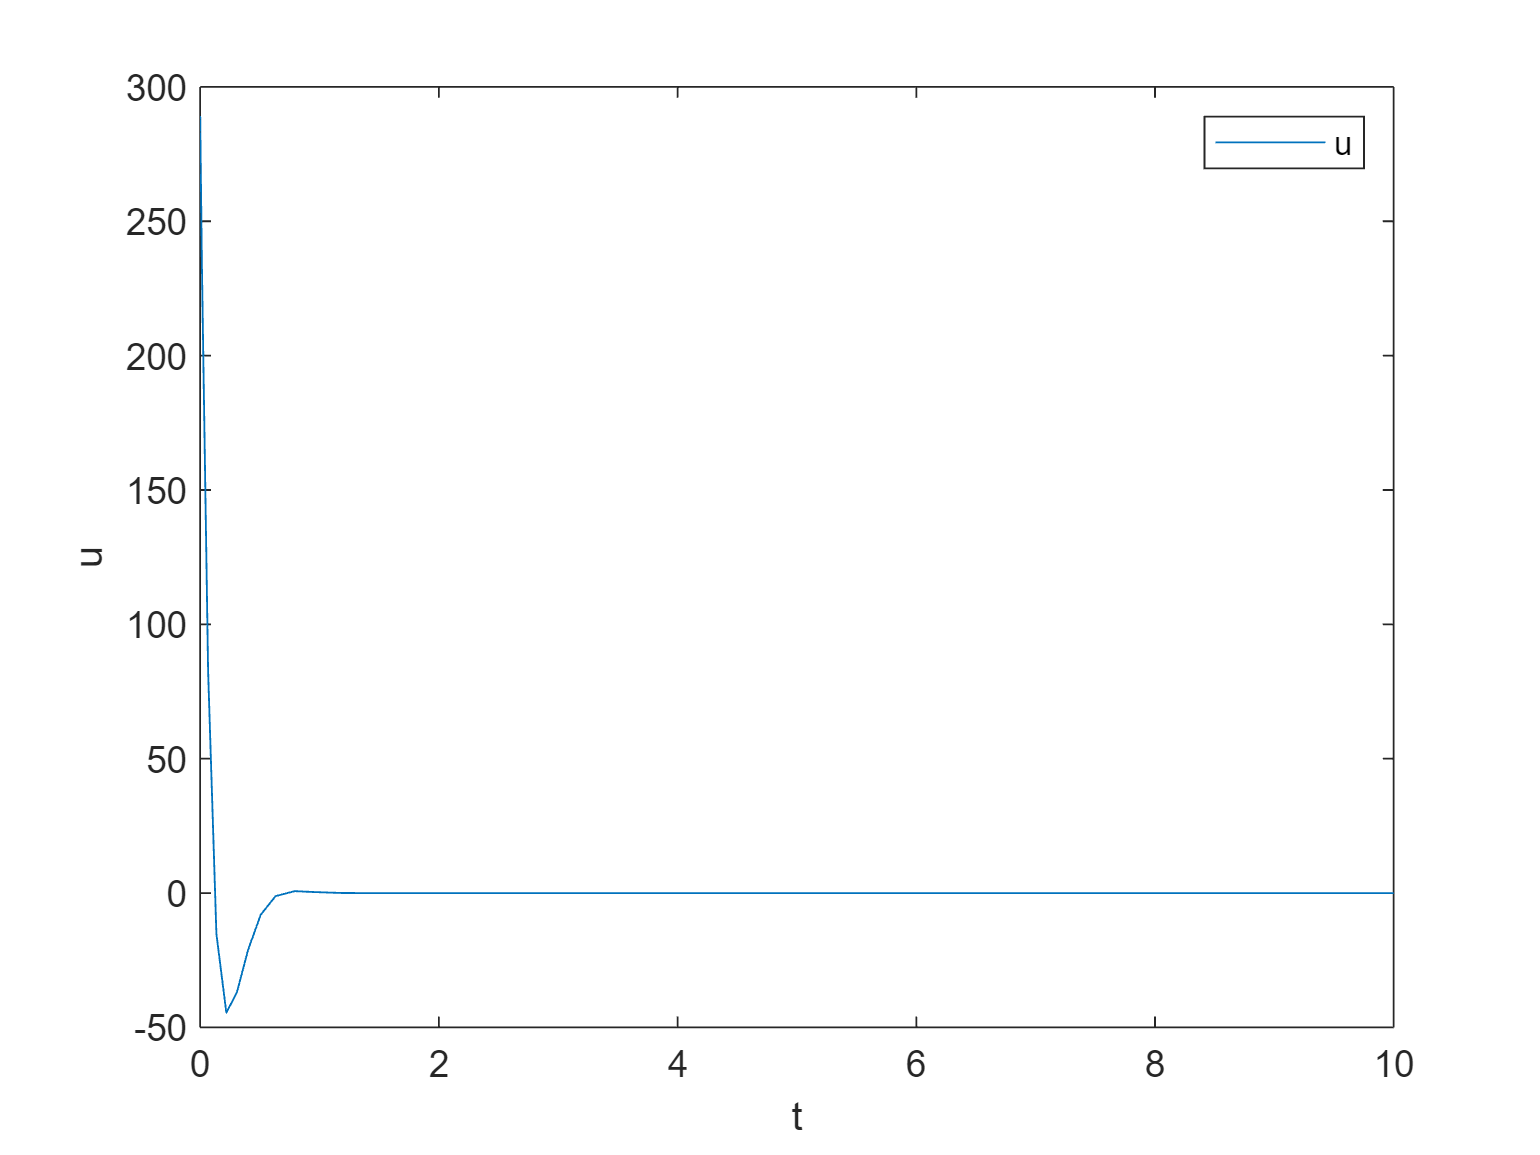

Step Information for the Output:
         RiseTime: 0.2591
    TransientTime: 0.3923
     SettlingTime: 0.3923
      SettlingMin: 3.1063
      SettlingMax: 3.1944
        Overshoot: 1.6818
       Undershoot: 0
             Peak: 3.1944
         PeakTime: 0.5072



%caso reale umax=300
Qz = [20 0; 0 0.08];
Qv = 3e-03; 
%caso estremo umax=+inf
%Qz = [1000 0; 0 0.001]
%Qv = 1e-08;
[K,S,P] = lqr(A,B,Qz,Qv);


simOut = sim('LQR_s_inv.slx', 'SimulationMode', 'normal');

% Chiamata alla funzione per visualizzare i risultati
plotSimulationResults_LQR(simOut,1);

Dall'ottimizzazione effettuata dal relativo comando Matlab, sono stati ottenuti risultati molto soddisfacenti, infatti tempo di salita e di assestamento sono in un ordine di grandezza molto basso, così come la sovraelongazione. Al momento fra i controllori proposti è quello migliore, poichè il trade off tra prestazioni e azioni di controllo è ottimale. A livello teorico ciò ha perfettamente senso, poichè nel primo caso stiamo effettuando una taratura empirica, nel secondo ci basiamo su una formulazione approssimativa della risposta del sistema, mentre in questo caso stiamo risolvendo un vero e proprio problema di ottimizzazione.

## **Proposta del controllore lineare, con azione integrale**

A seguito della progettazione dei precedenti controllori, si è deciso di apportare alcune modifiche per permettere l'introduzione dell'azione integrale. Questo poichè, a causa della realtà fisica del problema, sono presenti numerosi disturbi che potrebbero influenzarne il comportamento, tra cui sono state considerate: 

- **Forze di resistenza dell'aria, **essendo il sistema progettato per essere una mensola, essa può essere soggetta a questo tipo di fenomeni.

- **Generici errori di misura** durante il monitoraggio.

- **Perturbazioni esterne, vibrazioni, **che porterebbero il sistema a soffrire dell'azione di disturbi costanti

- **Perturbazioni termiche o deformazioni strutturali**

In generale quindi, sono stati considerati tutti quei disturbi costanti considerabili come delle spinte sul pendolo. In particolare, dato il limite di $300$ sull'azione di controllo, sono stati considerati disturbi dell'ordine dei $50$ per giustificare le scelte del controllore. Per l'aggiunta dell'azione integrale consideriamo il sistema alle differenze definito in $w=x_e-x$ e $v=u_e-u$:


$$\dot w = Aw+Bv \\ y = Cw$$


e introduciamo un nuovo stato: $\dot z= Cw -r$ ottenendo:


$$\dot w = Aw+Bv \\ y = Cw \\ \dot z = Cw-r$$


La nuova legge di controllo desiderata sarà $v(\cdot)=-kw - k_I z$ con la rimozione del termine $k_r$ poichè l'inseguimento del riferimento è garantito dall'azione integrale, e con l'aggiunta di questo termine.

La nuova dinamica sarà rappresentata da:


$$\tilde w =\left[\begin{array}{c} \dot w \\ \dot z\end{array}\right]=\left[\begin{array}{c} A & 0 \\ C & 0\end{array}\right]\left[\begin{array}{c} w \\ z\end{array}\right] + \left[\begin{array}{c} B\\ 0\end{array}\right] v  \;    +\left[\begin{array}{c} 0\\ -1\end{array}\right] r$$


Riunendo i termini affini, in termini di ingressi al sistema e esplicitando le matrici e identificandole con $A_s,B_s,C_s$ si ottiene:


$$A_s = \left[\begin{array}{c} 0 &1&0\\ 9.81 & -0.1&0\\1&0&0 \end{array}\right], \space\spaceB_s = \left[\begin{array}{c} 0 &0\\ 1 & 0 \\ 0 & -1\end{array}\right], \space\spaceC_s  = \left[\begin{array}{c}  1&0 &0\end{array}\right]$$


Per l’azione di controllo a retroazione di stato, non possiamo usare $B_s
$ del sistema esteso perché in tal caso otterremmo un $\tilde K$ riferito al sistema che ha come ingresso  $r$ e $v$, ma in realtà $r$ non è un grado di libertà e quindi dobbiamo imporre che $\tilde K$ abbia tante righe quanti sono gli ingressi $v$. Per questo useremo  $\hat B = \left[\begin{array}{c} 0 \\ 1 \\ 0 \end{array}\right]$.

Progettiamo $v = \tilde K \left[\begin{array}{c} w \\ z \end{array}\right]$ in cui $\tilde K =\left[\begin{array}{c} k_1 & k_2 & k_I \end{array}\right]$.  Esplicitiamo la legge di controllo $v = -k_1w_1-k_2w_2-k_Iz$ e riportiamola nelle nostre variabili di stato:


$$u = -k_1(x_1-x_{1e})-k_2(x_2-x_{2e})-k_I(\int [x_1-x_{1e}-(r-x_{1e})]dx)$$


E dato che nel nostro caso $r = \pi$ otteniamo:


$$u = -k_1x_1+k_1\pi-k_2x_2-k_I(\int [x_1-\pi]dx)$$


Prima di proseguire viene verificata la raggiungibilità:

clear all
close all
A=[0 1; 9.81 -0.1];
B=[0; 1];
C=[1 0];
D=0;

As=[0 1 0; 9.81 -0.1 0; 1 0 0];
Bs=[0 0; 1 0; 0 -1];

hatB=[0; 1; 0];

%matrice di raggiungibilità
W_Rs=[hatB As*hatB, As^2*hatB];
%verifichiamo che rango sia uguale a max(n righe, n colonne) di W_R
rank(W_Rs)

ans = 3

% Il sistema è raggiungibile

Il sistema è raggiungibile, poichè la matrice ha rango pieno.

Ulteriore nota del nostro sistema è che un disturbo costante che porti l'uscita del sistema a raggiungere valori maggiori della periodicità di $\pi$ è trattabile come un disturbo minore modificando il riferimento in maniera dinamica. Ovvero, dato che il riferimento costante $\pi$ è equiparabile a $3 \pi$, $5\pi$, valido anche nel caso lineare per $0$, $2\pi$ ecc.., e così via, quando è possibile, in seguito ad un disturbo, raggiungere più velocemente un riferimento piuttosto che un altro è preferibile come scelta. Di conseguenza è stato creato un modulo apposito che permette di modificare dinamicamente il riferimento a seconda dell'uscita attuale. 

Per quanto riguarda invece LQR, che è quello su cui ci soffermeremo, non cambiamo il riferimento ma il punto di equilibrio su cui stabilizzare il sistema, che fisicamente è lo stesso.

Ciò non è stato fatto per i riferimenti tempo varianti, perchè, in quel caso riscalare il riferimento ha un significato totalmente diverso in quanto la scelta di dare riferimenti con periodicità maggiore ha senso (effettuare giri del pendolo e così via...).

La funzione che implementa la logica di cambio dinamico di riferimento o punto di equilibrio è la seguente:

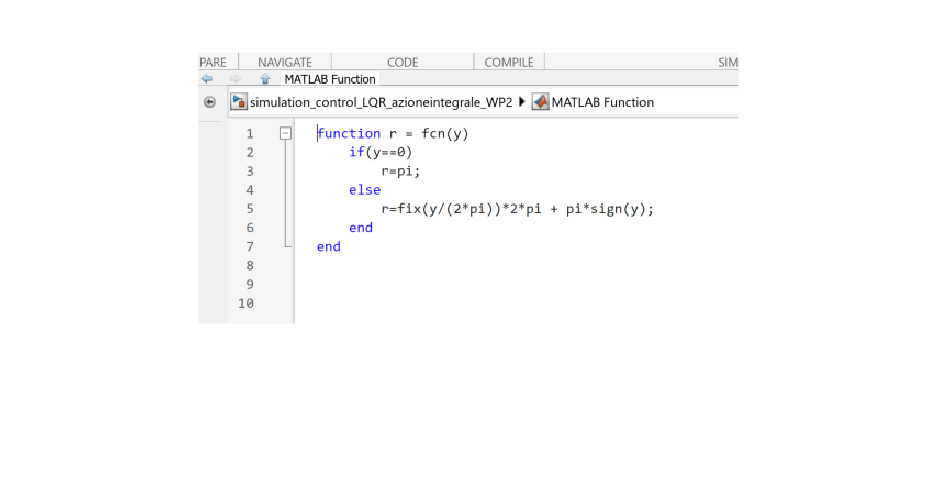

imshow(imread("img/reference_changing.png"))

## LQR (con azione integrale)

Per quanto riguarda il problema di ottimizzazione lineare quadratica nel caso con azione integrale è possibile proseguire con lo stesso ragionamento portato avanti fino a questo punto, ovvero tramite espansione dello stato, con l'aggiunta nel nuovo stato $\dot z$, e taratura delle conseguenti matrici sul nuovo sistema pesando di conseguenza anche l'azione integrale. Questo approccio è analogo a sfruttare la funzione offerta da Matlab **lqi** in cui l'espansione è effettuata dalla funzione stessa, e richiedendo matrici pesate anche per l'azione integrale. In questo caso lo schema di riferimento è:

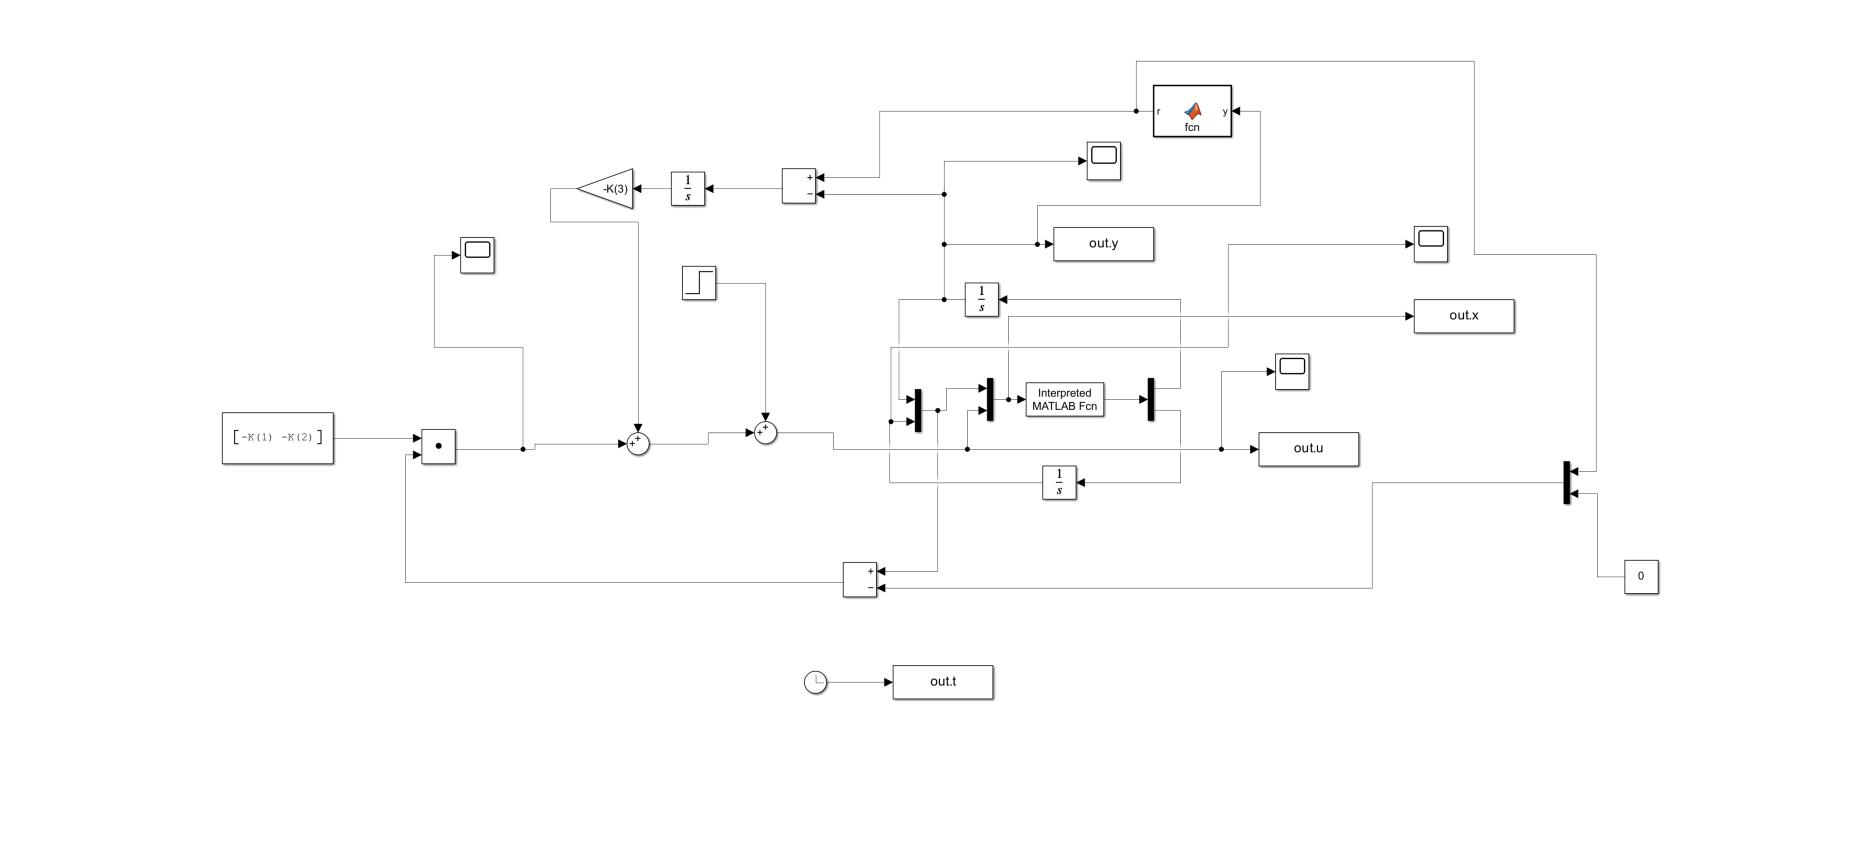

imshow(imread("img/lqr_integral_scheme.png"))

Dopo aver effettuato numerosi esperimenti si è ottenuto: 

clear all 
close all 

As=[0 1 0; 9.81 -0.1 0; 1 0 0]; 
Bs=[0 ; 1 ; 0 ]; 
%caso illimitato umax = +inf 
%Qz = [1000 0 0; 0 0.01 0; 0 0 1000] 
%Qv = 1e-08; 
 
A=[0 1; 9.81 -0.1]; 
B=[0; 1]; 
C=[1 0]; 
D=0; 
 
 % caso limitato umax = 300 
Qz = [2 0 0; 0 0.01 0; 0 0 0.5]; 
Qv = 3e-04; 
[K,S,e] = lqi(ss(A,B,C,D),Qz,Qv); 


## Test senza disturbo (con azione integrale)

Effettuiamo una comparazione con il caso precedente, ponendo il disturbo pari a $0$

close all
r=pi;
Disturbo = 0;
simOut = sim('LQR_s_inv_int', 'SimulationMode', 'normal'); 

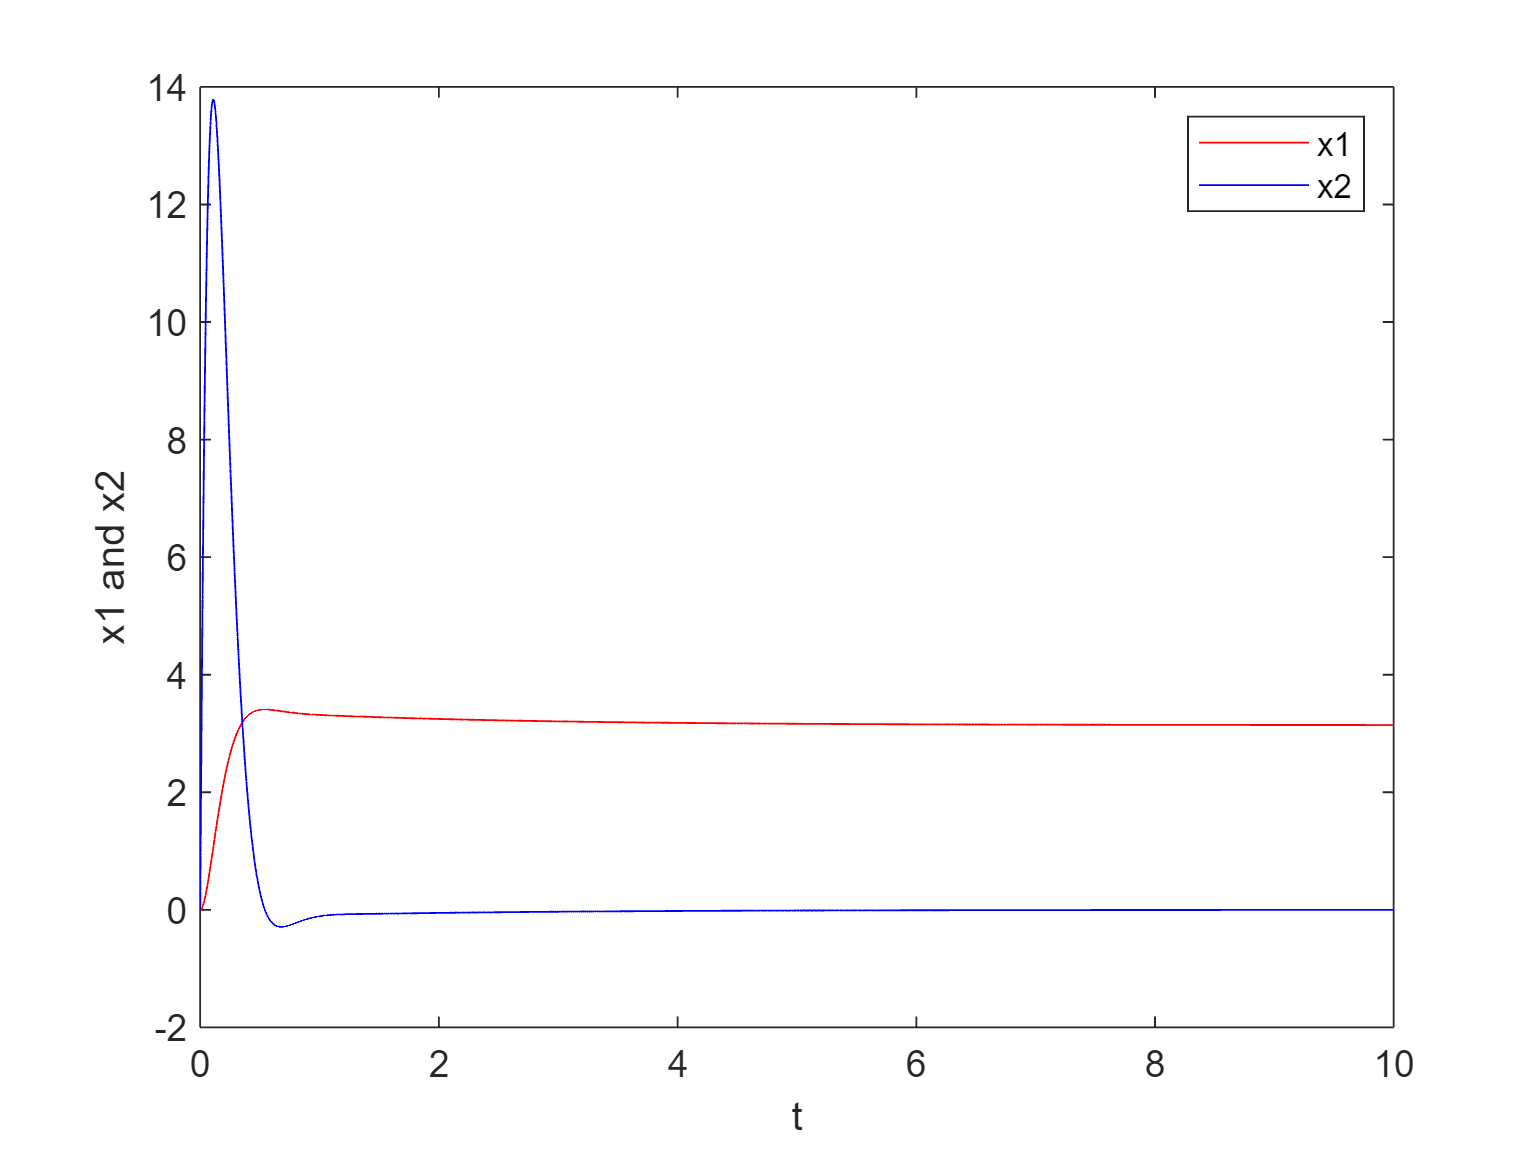

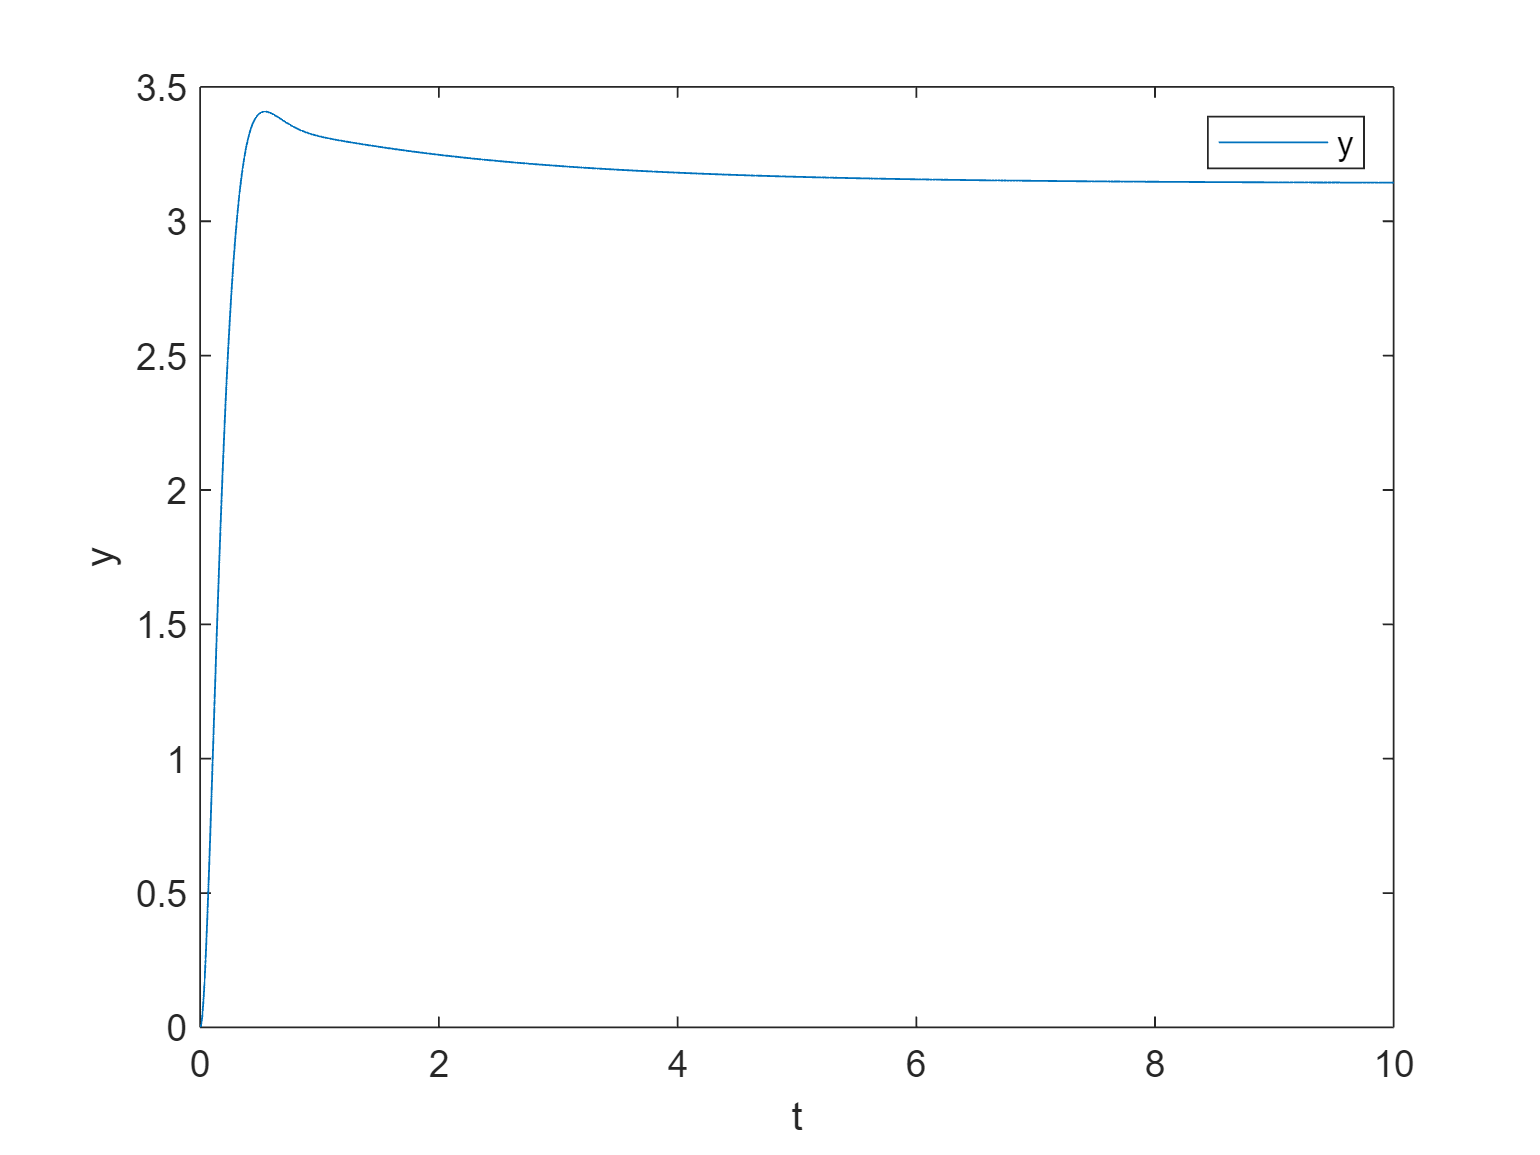

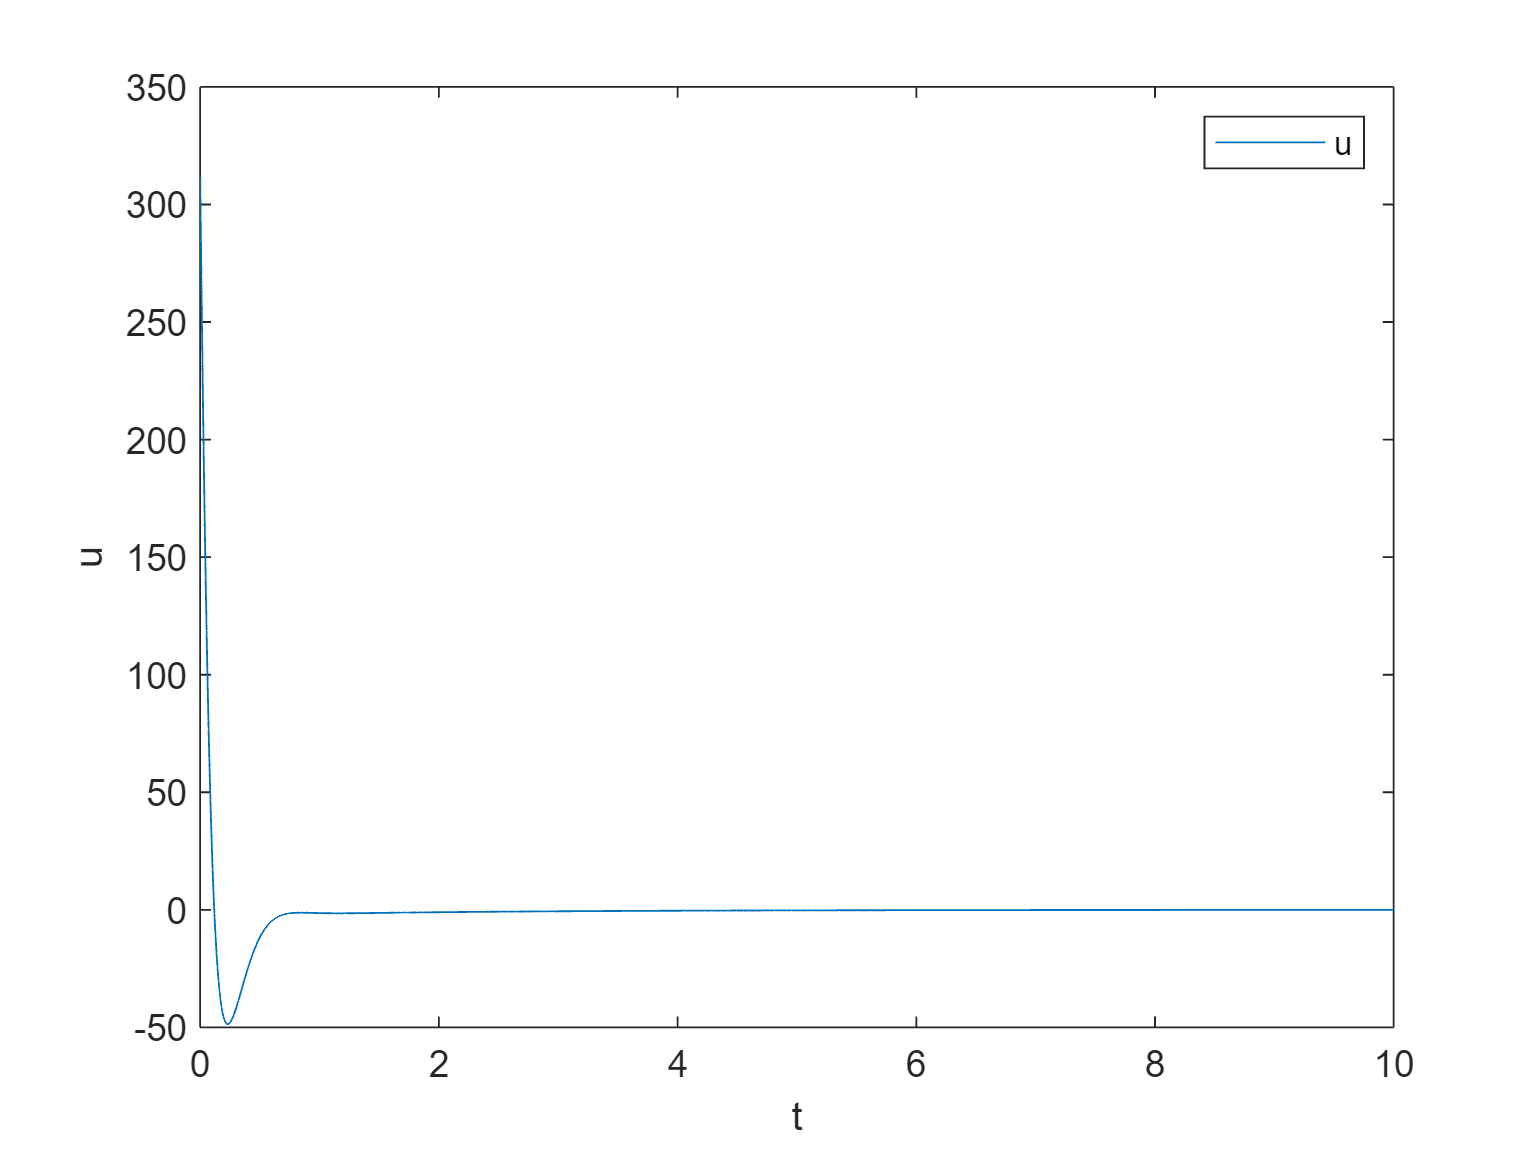

Step Information for the Output:
         RiseTime: 0.2248
    TransientTime: 2.9837
     SettlingTime: 2.9837
      SettlingMin: 2.8337
      SettlingMax: 3.4080
        Overshoot: 8.4104
       Undershoot: 0
             Peak: 3.4080
         PeakTime: 0.5419




% Chiamata alla funzione per visualizzare i risultati
plotSimulationResults_LQR(simOut,1);

Come si può notare, a parte il tempo di salita che è nell'ordine dell'LQR senza azione integrale, il sistema peggiora in sovraelongazione e tempo di assestamento. Ciò è dovuto all'azione integrale e alla limitatezza sullo sforzo di controllo. Di conseguenza le prestazioni sono si, peggiori rispetto al caso precedente, ma con l'aggiunta del disturbo riusciamo a garantire inseguimento del regime, cosa che non avviene per il caso senza azione integrale, infatti proseguiamo con l'introduzione del disturbo.

## Test con disturbo (con azione integrale)

close all
r=pi;
Disturbo = 50;
simOut = sim('LQR_s_inv_int', 'SimulationMode', 'normal'); 

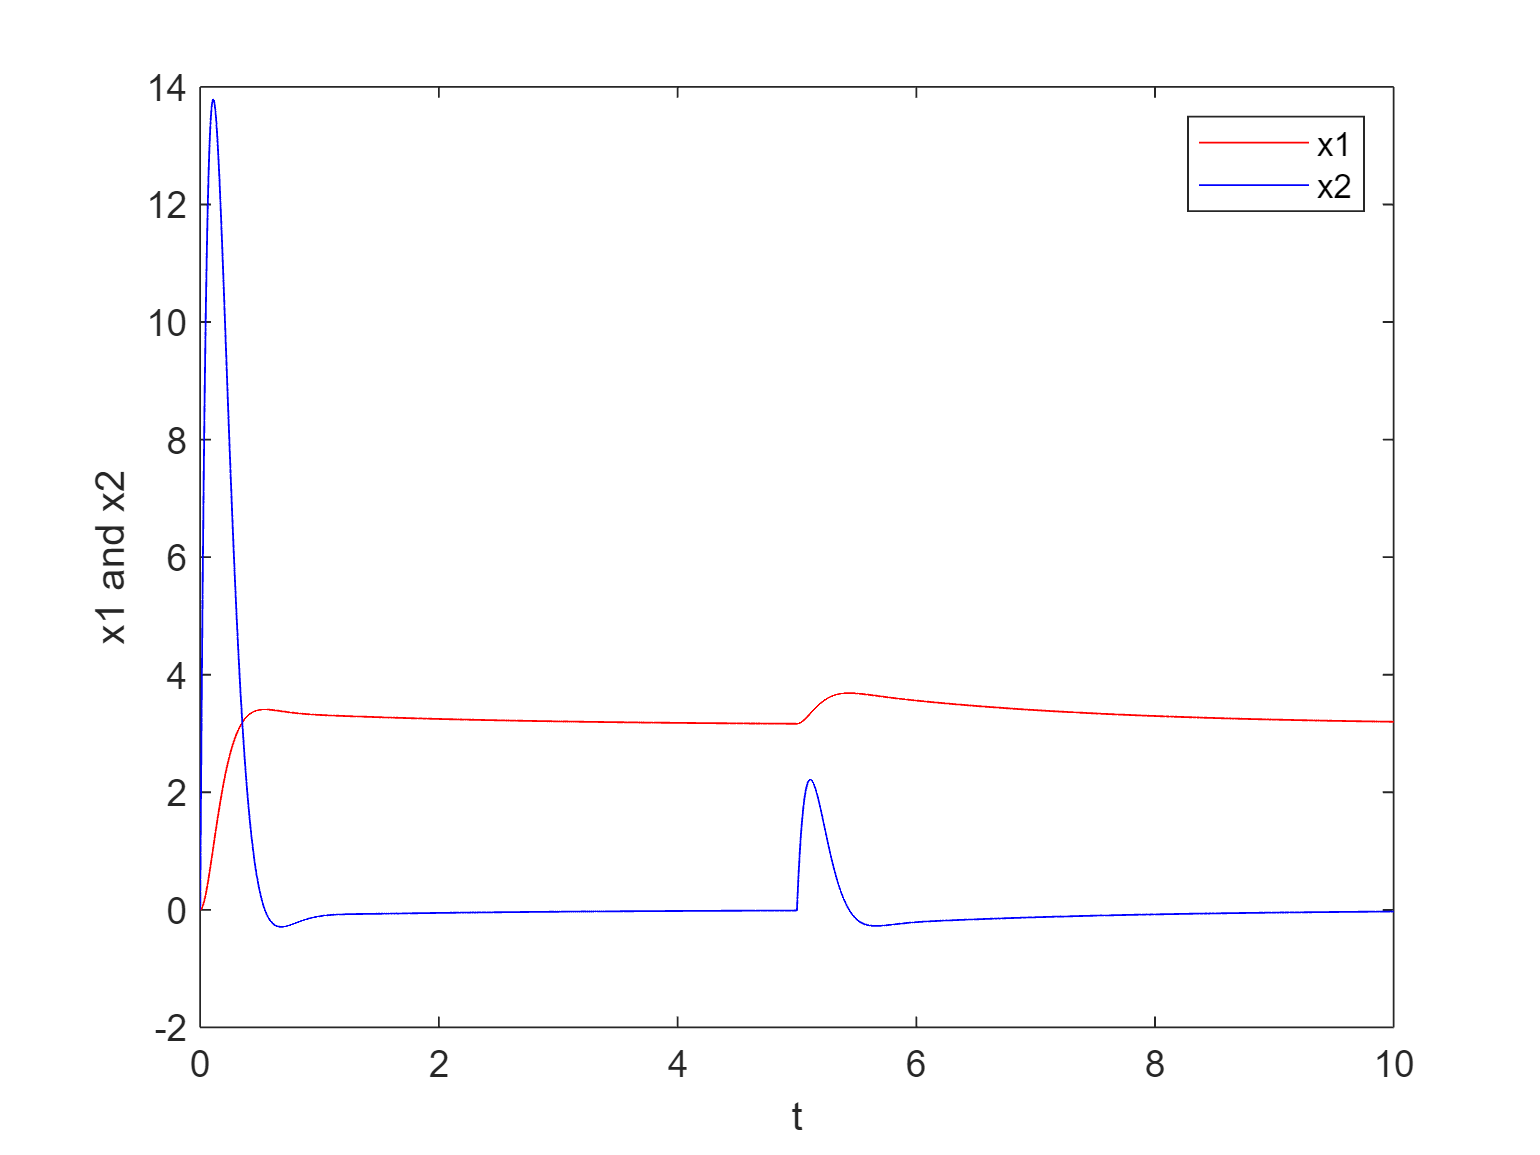

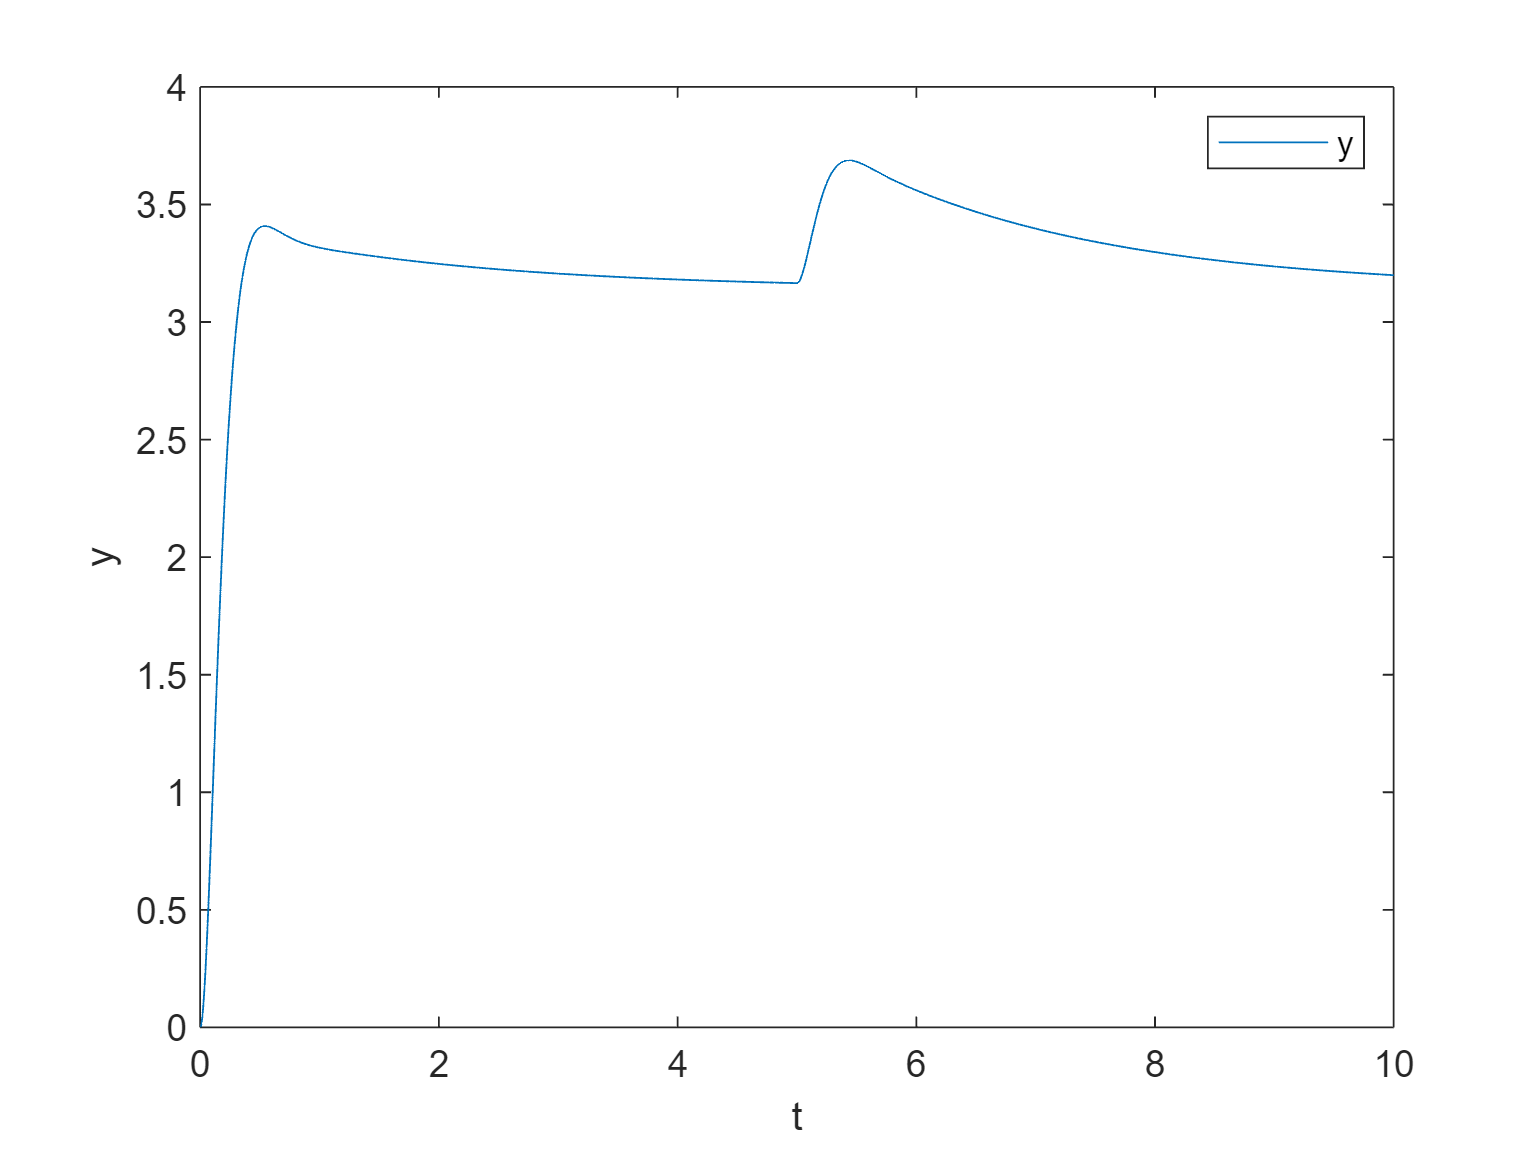

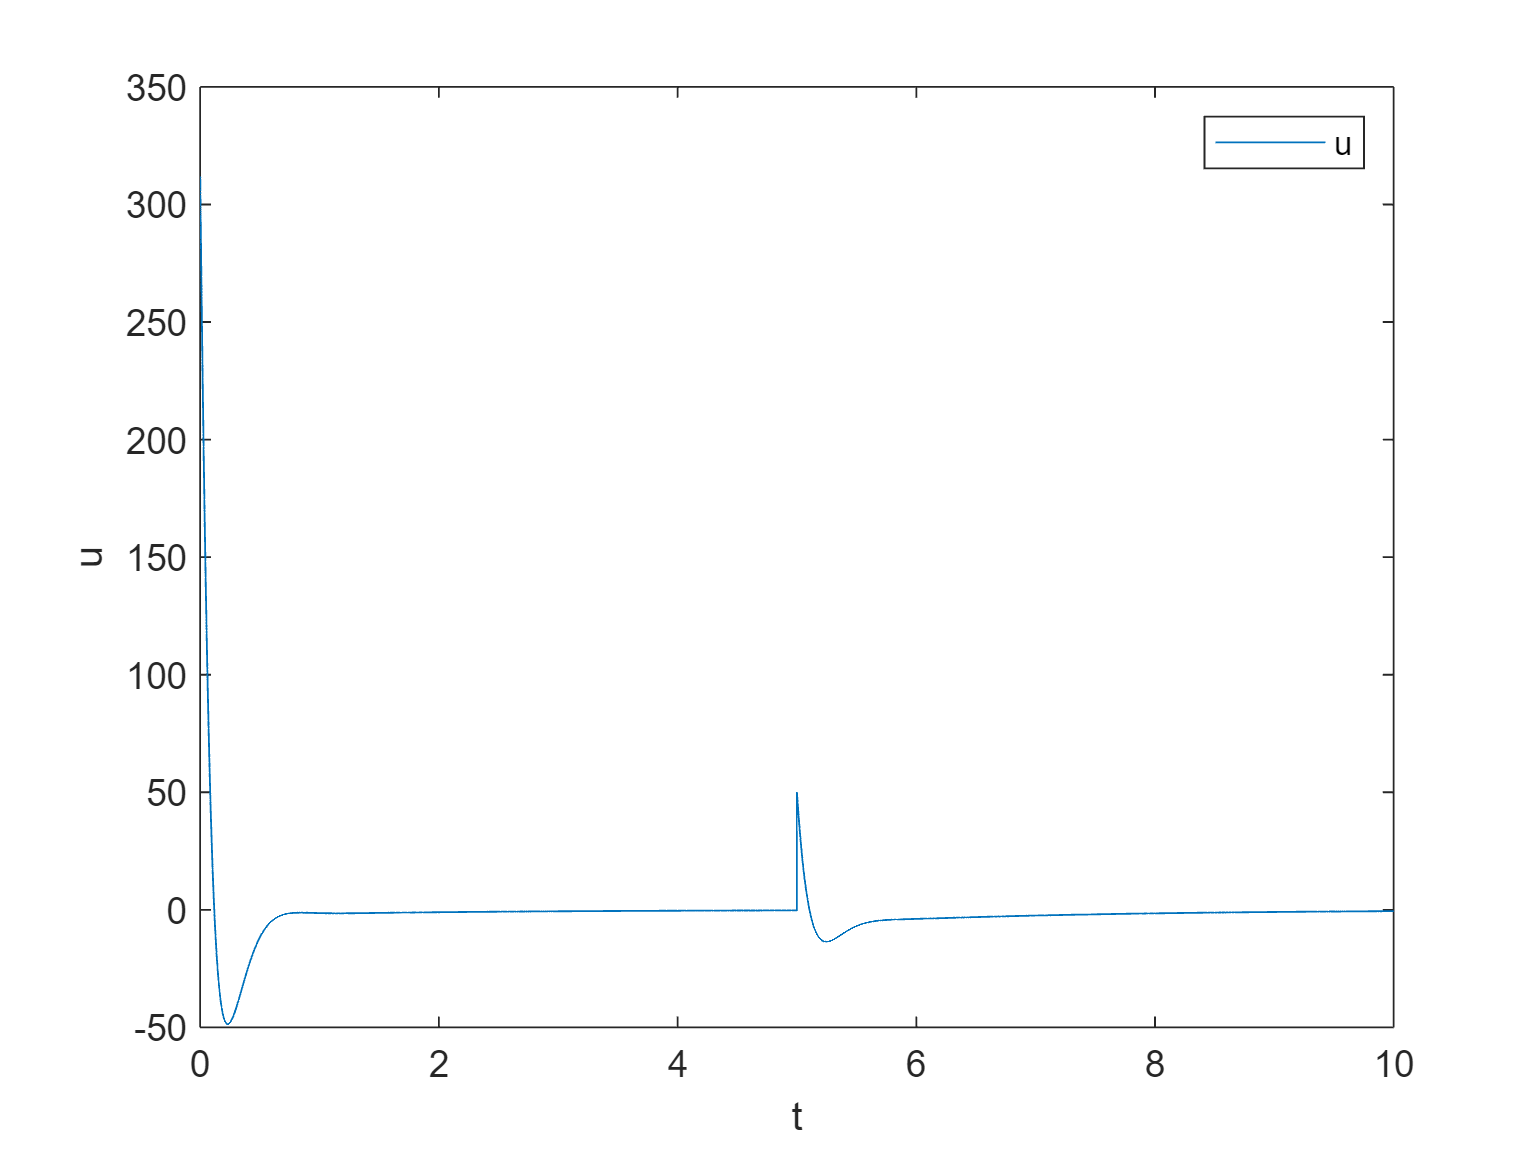

Step Information for the Output:
         RiseTime: 0.2324
    TransientTime: 8.4978
     SettlingTime: 8.4978
      SettlingMin: 2.8796
      SettlingMax: 3.6872
        Overshoot: 15.2511
       Undershoot: 0
             Peak: 3.6872
         PeakTime: 5.4375



% Chiamata alla funzione per visualizzare i risultati
plotSimulationResults_LQR(simOut,1);

Come notiamo riusciamo ad abbattere correttamente il disturbo, con un tempo pari a **SettlingTime** - **tempo in cui è inserito il disturbo **pari a $4.8160s$.Al termine di questa trattazione possiamo affermare che il miglior controllore trovato, in termini di prestazioni, è quello LQR senza azione integrale, ma se consideriamo che nella realtà fisica considerata i disturbi ci sono e sono anche molto frequenti, è stato scelto di proporre come controllore lineare l'LQR con azione integrale, detto anche LQI, date le sue prestazioni e la capacità di abbattere correttamente disturbi che potrebbero modificare la dinamica del sistema.